# Exploring contact-switching system designs compatible with level-2, pin-contact submanifolds

## Case 1: mult-disk, level-2

### Introduction and Kinematics

As shown in the previous paper, single disk-centered contact switching systems come with this inherent issue of inability to access the level-2, contact submanifolds where more than one feet is in contact and this is achieved by moving the legs to separate disks. We shall now consider one such system; a three-link system with the first and third link as pin-contacting legs, and the middle link is the body of the system. Consider the figure before for SE(2) frames and system description.

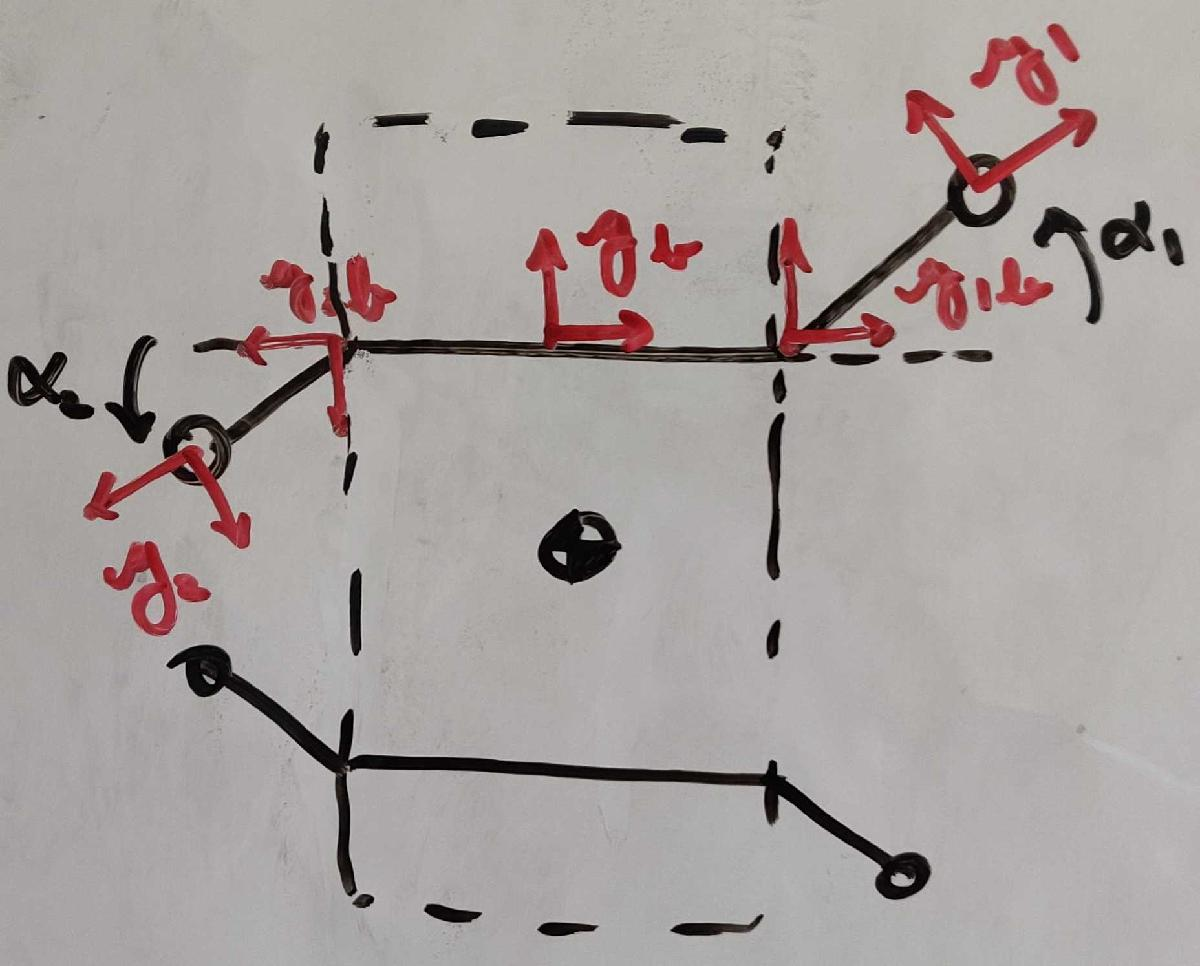

syms x y theta u v beta real

v2M_SE2 = @(v) [cos(v(3)), -sin(v(3)), v(1);
                sin(v(3)),  cos(v(3)), v(2);
                        0,         0,    1];

M2v_SE2 = @(M) simplify([M(1,3); 
                M(2,3);
                atan(M(2,1)/M(1,1))], 'Steps', 10, ...
                'IgnoreAnalyticConstraints', true);

L_h_ofg = @(g,h) simplify(M2v_SE2(v2M_SE2(h)*v2M_SE2(g)), ...
    'Steps', 10, 'IgnoreAnalyticConstraints', true); 
R_h_ofg = @(g,h) simplify(M2v_SE2(v2M_SE2(g)*v2M_SE2(h)), ...
    'Steps', 10, 'IgnoreAnalyticConstraints', true); 

T_gL_h = @(g,h) jacobian(L_h_ofg(g,h), g); T_gR_h = @(g,h) jacobian(R_h_ofg(g,h), g);

g_vec = [x;
         y;
         theta];
h_vec = [u;
         v;
         beta];

g_mat = v2M_SE2(g_vec);

T_g_to_T_hg = T_gL_h(g_vec, h_vec);
T_g_to_T_gh = T_gR_h(g_vec, h_vec);

gInv_mat = simplify(inv(g_mat), 'Steps', 10);
gInv_vec = M2v_SE2(gInv_mat);

TgLgInv = simplify(subs(T_g_to_T_hg, [x, y, theta, u, v, beta],...
    [x, y, theta, gInv_vec(1), gInv_vec(2), gInv_vec(3)]));
TeRg = simplify(subs(T_g_to_T_gh, [x, y, theta, u, v, beta], ...
                [0, 0, 0, x, y, theta]));
AdjInvMap = @(k) simplify(...
    subs(TgLgInv, theta, k(3))*subs(TeRg, [x y], [k(1) k(2)])...
    , 'Steps', 10);

theta_circ = [0,0,1]'; x_circ = [1,0,0]'; y_circ = [0,1,0]';

Now, let's make sure that the workspaces of the legs don't intersect each other. Make the lateral distance between the legs '2l', and the vertical distance between leg pairs 12 and 34 as also 2l; making the legs on the same side of the body not have intersecting workspaces and makes the body a square with the leg bases at each corner; note that the legs on the contra-lateral sides of the body have their workspaces mirrored like in any robotic system, **prioritizing forward motion**.

syms a l real positive
assume(a<=1);
syms alpha_1 alpha_2 alpha_3 alpha_4 real

% 12b is the base frame at the center of the link connecting legs 1 and 2.
% Similarly, for 34b as well.

h_b__12b = [0, l, 0]';
h_b__34b = [0, -l, 0]';


h_12b__1b = [l, 0, 0]';
h_12b__2b = [-l, 0, pi]';
h_34b__3b = [-l, 0, pi]';
h_34b__4b = [l, 0, 0]';

syms alpha_i
h_ib__i = [a*l*[cos(alpha_i); sin(alpha_i)]; alpha_i];
h_ib__i_func = matlabFunction(h_ib__i, 'Vars', [a, l, alpha_i]);
J_ib__i = AdjInvMap(h_ib__i);
J_ib__i_func = matlabFunction(J_ib__i, 'Vars', [a, l, alpha_i]);
J_ib__j_func = matlabFunction(zeros(3,3), 'Vars', [a, l, alpha_i]);
% Jacobian to a leg from a different leg base will always be zero.

% Need to find a better, less repetitive way of doing this; the first
% thought would be to define loop iteration based strings and convert them
% to a variable name -- CHECK OUT "genvarname"
h_1b__1 = h_ib__i_func(a,l,alpha_1);
h_2b__2 = h_ib__i_func(a,l,alpha_2);
h_3b__3 = h_ib__i_func(a,l,alpha_3);
h_4b__4 = h_ib__i_func(a,l,alpha_4);

J_1b__1 = AdjInvMap(h_1b__1);
J_2b__2 = AdjInvMap(h_2b__2);
J_3b__3 = AdjInvMap(h_3b__3);
J_4b__4 = AdjInvMap(h_4b__4);

J_1b__2 = J_ib__j_func(a,l,alpha_1);
J_1b__3 = J_ib__j_func(a,l,alpha_1);
J_1b__4 = J_ib__j_func(a,l,alpha_1);

J_2b__1 = J_ib__j_func(a,l,alpha_2);
J_2b__3 = J_ib__j_func(a,l,alpha_2);
J_2b__4 = J_ib__j_func(a,l,alpha_2);

J_3b__1 = J_ib__j_func(a,l,alpha_3);
J_3b__2 = J_ib__j_func(a,l,alpha_3);
J_3b__4 = J_ib__j_func(a,l,alpha_3);

J_4b__1 = J_ib__j_func(a,l,alpha_4);
J_4b__2 = J_ib__j_func(a,l,alpha_4);
J_4b__3 = J_ib__j_func(a,l,alpha_4);

h_b__1b = M2v_SE2(v2M_SE2(h_b__12b)*...
    v2M_SE2(h_12b__1b));
h_b__2b = M2v_SE2(v2M_SE2(h_b__12b)*...
    v2M_SE2(h_12b__2b));
h_b__3b = M2v_SE2(v2M_SE2(h_b__34b)*...
    v2M_SE2(h_34b__3b));
h_b__4b = M2v_SE2(v2M_SE2(h_b__34b)*...
    v2M_SE2(h_34b__4b));

h_b__1 = M2v_SE2(v2M_SE2(h_b__12b)*...
    v2M_SE2(h_12b__1b)*v2M_SE2(h_1b__1));
h_b__2 = M2v_SE2(v2M_SE2(h_b__12b)*...
    v2M_SE2(h_12b__2b)*v2M_SE2(h_2b__2));
h_b__3 = M2v_SE2(v2M_SE2(h_b__34b)*...
    v2M_SE2(h_34b__3b)*v2M_SE2(h_3b__3));
h_b__4 = M2v_SE2(v2M_SE2(h_b__34b)*...
    v2M_SE2(h_34b__4b)*v2M_SE2(h_4b__4));

J_b__1 = AdjInvMap(M2v_SE2(v2M_SE2(h_b__12b)*...
    v2M_SE2(h_12b__1b)*v2M_SE2(h_1b__1)));
J_b__2 = AdjInvMap(M2v_SE2(v2M_SE2(h_b__12b)*...
    v2M_SE2(h_12b__2b)*v2M_SE2(h_2b__2)));
J_b__3 = AdjInvMap(M2v_SE2(v2M_SE2(h_b__34b)*...
    v2M_SE2(h_34b__3b)*v2M_SE2(h_3b__3)));
J_b__4 = AdjInvMap(M2v_SE2(v2M_SE2(h_b__34b)*...
    v2M_SE2(h_34b__4b)*v2M_SE2(h_4b__4)));

% Get the full Jacobian:
J_1_full = [J_b__1,...
    J_1b__1*theta_circ, J_2b__1*theta_circ, J_3b__1*theta_circ, J_4b__1*theta_circ];
J_2_full = [J_b__2,...
    J_1b__2*theta_circ, J_2b__2*theta_circ, J_3b__2*theta_circ, J_4b__2*theta_circ];
J_3_full = [J_b__3,...
    J_1b__3*theta_circ, J_2b__3*theta_circ, J_3b__3*theta_circ, J_4b__3*theta_circ];
J_4_full = [J_b__4,...
    J_1b__4*theta_circ, J_2b__4*theta_circ, J_3b__4*theta_circ, J_4b__4*theta_circ];

% % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % TRANSFORM VALIDAITON COMPLETE
% Let's plot the robot and convince ourselves that the transforms are
% right.
base_topbase_x = [0 h_b__12b(1)]; base_topbase_y = [0 h_b__12b(2)];
base_botbase_x = [0 h_b__34b(1)]; base_botbase_y = [0 h_b__34b(2)];

topbase_leg1base_x = [h_b__12b(1) h_b__1b(1)]; topbase_leg1base_y = [h_b__12b(2) h_b__1b(2)];
topbase_leg2base_x = [h_b__12b(1) h_b__2b(1)]; topbase_leg2base_y = [h_b__12b(2) h_b__2b(2)];

botbase_leg3base_x = [h_b__34b(1) h_b__3b(1)]; botbase_leg3base_y = [h_b__34b(2) h_b__3b(2)];
botbase_leg4base_x = [h_b__34b(1) h_b__4b(1)]; botbase_leg4base_y = [h_b__34b(2) h_b__4b(2)];

legbase1_leg1_x =  [h_b__1b(1) h_b__1(1)]; legbase1_leg1_y =  [h_b__1b(2) h_b__1(2)];
legbase2_leg2_x =  [h_b__2b(1) h_b__2(1)]; legbase2_leg2_y =  [h_b__2b(2) h_b__2(2)];
legbase3_leg3_x =  [h_b__3b(1) h_b__3(1)]; legbase3_leg3_y =  [h_b__3b(2) h_b__3(2)];
legbase4_leg4_x =  [h_b__4b(1) h_b__4(1)]; legbase4_leg4_y =  [h_b__4b(2) h_b__4(2)];

base_topbase_x = double(subs(base_topbase_x,l,1)); base_topbase_y = double(subs(base_topbase_y,l,1));
base_botbase_x = double(subs(base_botbase_x,l,1)); base_botbase_y = double(subs(base_botbase_y,l,1));

topbase_leg1base_x = double(subs(topbase_leg1base_x,l,1)); topbase_leg1base_y = double(subs(topbase_leg1base_y,l,1));
topbase_leg2base_x = double(subs(topbase_leg2base_x,l,1)); topbase_leg2base_y = double(subs(topbase_leg2base_y,l,1));

botbase_leg3base_x = double(subs(botbase_leg3base_x,l,1)); botbase_leg3base_y = double(subs(botbase_leg3base_y,l,1));
botbase_leg4base_x = double(subs(botbase_leg4base_x,l,1)); botbase_leg4base_y = double(subs(botbase_leg4base_y,l,1));

legbase1_leg1_x =  double(subs(legbase1_leg1_x,[a,l,alpha_1],[1,1,0])); legbase1_leg1_y = double(subs(legbase1_leg1_y,[a,l,alpha_1],[1,1,0]));
legbase2_leg2_x =  double(subs(legbase2_leg2_x,[a,l,alpha_2],[1,1,0])); legbase2_leg2_y = double(subs(legbase2_leg2_y,[a,l,alpha_2],[1,1,0]));
legbase3_leg3_x =  double(subs(legbase3_leg3_x,[a,l,alpha_3],[1,1,0])); legbase3_leg3_y = double(subs(legbase3_leg3_y,[a,l,alpha_3],[1,1,0]));
legbase4_leg4_x =  double(subs(legbase4_leg4_x,[a,l,alpha_4],[1,1,0])); legbase4_leg4_y = double(subs(legbase4_leg4_y,[a,l,alpha_4],[1,1,0]));

figure()

plot(base_topbase_x,base_topbase_y,'k--','LineWidth',1.2);
hold on; grid on;
plot(base_botbase_x,base_botbase_y,'k--','LineWidth',1.2);
plot(topbase_leg1base_x,topbase_leg1base_y,'k','LineWidth',2.0);
plot(topbase_leg2base_x,topbase_leg2base_y,'k','LineWidth',2.0);
plot(botbase_leg3base_x,botbase_leg3base_y,'k','LineWidth',2.0);
plot(botbase_leg4base_x,botbase_leg4base_y,'k','LineWidth',2.0);

plot(legbase1_leg1_x,legbase1_leg1_y,'ks-','LineWidth',2.0);
plot(legbase2_leg2_x,legbase2_leg2_y,'ks-','LineWidth',2.0);
plot(legbase3_leg3_x,legbase3_leg3_y,'ks-','LineWidth',2.0);
plot(legbase4_leg4_x,legbase4_leg4_y,'ks-','LineWidth',2.0);
legbase1_leg1_x =  [h_b__1b(1) h_b__1(1)]; legbase1_leg1_y =  [h_b__1b(2) h_b__1(2)];
legbase2_leg2_x =  [h_b__2b(1) h_b__2(1)]; legbase2_leg2_y =  [h_b__2b(2) h_b__2(2)];
legbase3_leg3_x =  [h_b__3b(1) h_b__3(1)]; legbase3_leg3_y =  [h_b__3b(2) h_b__3(2)];
legbase4_leg4_x =  [h_b__4b(1) h_b__4(1)]; legbase4_leg4_y =  [h_b__4b(2) h_b__4(2)];
legbase1_leg1_x =  double(subs(legbase1_leg1_x,[a,l,alpha_1],[1,1,pi/3])); legbase1_leg1_y = double(subs(legbase1_leg1_y,[a,l,alpha_1],[1,1,pi/3]));
legbase2_leg2_x =  double(subs(legbase2_leg2_x,[a,l,alpha_2],[1,1,pi/3])); legbase2_leg2_y = double(subs(legbase2_leg2_y,[a,l,alpha_2],[1,1,pi/3]));
legbase3_leg3_x =  double(subs(legbase3_leg3_x,[a,l,alpha_3],[1,1,pi/3])); legbase3_leg3_y = double(subs(legbase3_leg3_y,[a,l,alpha_3],[1,1,pi/3]));
legbase4_leg4_x =  double(subs(legbase4_leg4_x,[a,l,alpha_4],[1,1,pi/3])); legbase4_leg4_y = double(subs(legbase4_leg4_y,[a,l,alpha_4],[1,1,pi/3]));
figure()
plot(base_topbase_x,base_topbase_y,'k--','LineWidth',1.2);
hold on; grid on;
plot(base_botbase_x,base_botbase_y,'k--','LineWidth',1.2);
plot(topbase_leg1base_x,topbase_leg1base_y,'k','LineWidth',2.0);
plot(topbase_leg2base_x,topbase_leg2base_y,'k','LineWidth',2.0);
plot(botbase_leg3base_x,botbase_leg3base_y,'k','LineWidth',2.0);
plot(botbase_leg4base_x,botbase_leg4base_y,'k','LineWidth',2.0);
plot(legbase1_leg1_x,legbase1_leg1_y,'ks-','LineWidth',2.0);
plot(legbase2_leg2_x,legbase2_leg2_y,'ks-','LineWidth',2.0);
plot(legbase3_leg3_x,legbase3_leg3_y,'ks-','LineWidth',2.0);
plot(legbase4_leg4_x,legbase4_leg4_y,'ks-','LineWidth',2.0);

C = [eye(2,2),zeros(2,1)];

pfaff_12 = [C*J_1_full;
            C*J_2_full];
pfaff_23 = [C*J_2_full;
            C*J_3_full];
pfaff_34 = [C*J_3_full;
            C*J_4_full];
pfaff_41 = [C*J_4_full;
            C*J_1_full];
pfaff_13 = [C*J_1_full;
            C*J_3_full];
pfaff_24 = [C*J_2_full;
            C*J_4_full];

% Compute the local connection for the 12 submanifold -- just gives inf
% % simplify(pfaff_12(:,1:3)\pfaff_12(:,4:end),'Steps',10)
% % simplify(pfaff_23(:,1:3)\pfaff_23(:,4:end),'Steps',10)
% % simplify(pfaff_34(:,1:3)\pfaff_34(:,4:end),'Steps',10)
% % simplify(pfaff_41(:,1:3)\pfaff_41(:,4:end),'Steps',10)
% % simplify(pfaff_13(:,1:3)\pfaff_13(:,4:end),'Steps',10)
% % simplify(pfaff_24(:,1:3)\pfaff_24(:,4:end),'Steps',10)

Since, no connection exists, let us look at the formulation for squared inter-leg distance to glean some insight into why this is the case.

ksq_12 = simplify((C*(h_b__2 - h_b__1))'*C*(h_b__2 - h_b__1),'Steps',10)

$$ksq\_12 = l^{2}\,{\left(a\,\cos\left(\alpha_{1}\right)+a\,\cos\left(\alpha_{2}\right)+2\right)}^{2}+a^{2}\,l^{2}\,{\left(\sin\left(\alpha_{1}\right)+\sin\left(\alpha_{2}\right)\right)}^{2}$$

ksq_23 = simplify((C*(h_b__3 - h_b__2))'*C*(h_b__3 - h_b__2),'Steps',10)

$$ksq\_23 = l^{2}\,{\left(a\,\sin\left(\alpha_{3}\right)-a\,\sin\left(\alpha_{2}\right)+2\right)}^{2}+a^{2}\,l^{2}\,{\left(\cos\left(\alpha_{2}\right)-\cos\left(\alpha_{3}\right)\right)}^{2}$$

ksq_34 = simplify((C*(h_b__4 - h_b__3))'*C*(h_b__4 - h_b__3),'Steps',10)

$$ksq\_34 = l^{2}\,{\left(a\,\cos\left(\alpha_{3}\right)+a\,\cos\left(\alpha_{4}\right)+2\right)}^{2}+a^{2}\,l^{2}\,{\left(\sin\left(\alpha_{3}\right)+\sin\left(\alpha_{4}\right)\right)}^{2}$$

ksq_41 = simplify((C*(h_b__1 - h_b__4))'*C*(h_b__1 - h_b__4),'Steps',10)

$$ksq\_41 = l^{2}\,{\left(a\,\sin\left(\alpha_{1}\right)-a\,\sin\left(\alpha_{4}\right)+2\right)}^{2}+a^{2}\,l^{2}\,{\left(\cos\left(\alpha_{1}\right)-\cos\left(\alpha_{4}\right)\right)}^{2}$$

ksq_13 = simplify((C*(h_b__3 - h_b__1))'*C*(h_b__3 - h_b__1),'Steps',10)

$$ksq\_13 = {\left(l\,\left(a\,\cos\left(\alpha_{1}\right)+1\right)+l\,\left(a\,\cos\left(\alpha_{3}\right)+1\right)\right)}^{2}+{\left(l\,\left(a\,\sin\left(\alpha_{1}\right)+1\right)+l\,\left(a\,\sin\left(\alpha_{3}\right)+1\right)\right)}^{2}$$

ksq_24 = simplify((C*(h_b__4 - h_b__2))'*C*(h_b__4 - h_b__2),'Steps',10)

$$ksq\_24 = {\left(l\,\left(a\,\cos\left(\alpha_{2}\right)+1\right)+l\,\left(a\,\cos\left(\alpha_{4}\right)+1\right)\right)}^{2}+{\left(l\,\left(a\,\sin\left(\alpha_{2}\right)-1\right)+l\,\left(a\,\sin\left(\alpha_{4}\right)-1\right)\right)}^{2}$$

ksq_12_func = matlabFunction(ksq_12,'Vars',[a, l, alpha_1, alpha_2]);

Let's just plot this as a function of the shape space in the form of a heat-map to see if there are tractable connection regions.

dnum = 100;

aa = 1;                                 
ll = 1;                                 

ank = pi/4;                    

xx = linspace(-ank,ank,dnum);          
yy = xx;

[a1,a2] = meshgrid(xx,yy);

ksq_sweep = ksq_12_func(aa, ll, a1, a2);
ksq_M = ksq_12_func(aa, ll, xx, yy);
ksq_m = ksq_12_func(aa, ll, xx, -yy);
ksq_x = ksq_12_func(aa, ll, xx, 0*yy);
ksq_y = ksq_12_func(aa, ll, 0*xx, yy);

% Plot the inter-leg distance landscape
figure('units','pixels','position',[0 0 1920 1080],'Color','w')
surf(a1,a2,ksq_sweep,'EdgeColor','none'); % ,'EdgeColor','none'
axis equal tight; hold on; view(2);
colormap(jet); % use this colormap
colorbar(); % show the colorbar
line(xx,yy,ksq_M,'Color','k','LineStyle','-'); % major axis % ,'LineWidth',1.2
line(xx,-yy,ksq_m,'Color','k','LineStyle','--');% minor axis % ,'LineWidth',1.2
line(0*xx,yy,ksq_y,'Color','k','LineStyle',':');% alpha_j axis % ,'LineWidth',1.2
line(xx,0*yy,ksq_x,'Color','k','LineStyle',':');% alpha_i-axis % ,'LineWidth',1.2
xlabel('$\alpha_1$','Interpreter','latex',FontSize=20);
ylabel('$\alpha_2$','Interpreter','latex',FontSize=20);
title('$k^2_{12}$','Interpreter','latex',FontSize=20);

Seems like the inter-leg distance is definitely changing as we move along any direction, but there are level-set contours that from a loop in the shape space. This should be the same for all leg pairs. Hence, to expand our shape-space, let's try adding compliance through a contra-laterally symmetric, closed kinematic chain -- half a sarrus linkage! **Disclaimer: **You also need to add an out of plane chain to constrain the robot shape...

Also, the pseudo-inverse should work, let's do some additional digging.

### Overconstrained, inconsistent 4x3 subblock

Adding some analysis on the pseudoinverse of the overconstrained 4x3 sub-block (from the left) which happens to be inconsistent.

s_12 = pfaff_12(:,1:3); s_23 = pfaff_23(:,1:3); s_34 = pfaff_34(:,1:3); s_41 = pfaff_41(:,1:3); % adjacent legs
s_13 = pfaff_13(:,1:3); s_24 = pfaff_24(:,1:3); % diagonally opposite legs

As checked in the previous section, both '\' and pinv has failed us due to some symbolic engine issues; hence, we shall check if the sub-blocks are full column rank (needed to implement the inverse) and then implement a pseudoinverse (Moore-Penrose Inverse) manually.

% Let's check the column rank with rank command and also check the row
% reduced echelon form as proof:
rank(s_12)

ans = 3

rref(s_12)

$$ans = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1\\ 0 & 0 & 0 \end{array}\right)$$

% Uncomment the functions below to obtain the approximated, least squares
% minimum local connection for this system.

The rank and echelon form reveal that the sub-block is full rank, but still the pinv and backlash command are causing issues for us. Let's make sure this is the case for all other contact submanifolds as well!

% rank(s_23)
% rref(s_23)
% rank(s_34)
% rref(s_34)
% rank(s_41)
% rref(s_41)
% rank(s_13)
% rref(s_13)
% rank(s_24)
% rref(s_24)
% % Uncomment above to verify the full column rank requirement to take the
% pseudoinverse.

They too work out! Now, we are good to take the pseudoinverse (and simplify the result)!

% s_12p = simplify(transpose(s_12)*s_12*transpose(s_12));
% s_23p = simplify(transpose(s_23)*s_23*transpose(s_23));
% s_34p = simplify(transpose(s_34)*s_34*transpose(s_34));
% s_41p = simplify(transpose(s_41)*s_41*transpose(s_41));
% s_13p = simplify(transpose(s_13)*s_13*transpose(s_13));
% s_24p = simplify(transpose(s_24)*s_24*transpose(s_24));

Get the approximate, least squares, local connection ${}^+\!\! A$ for each two-foot contact submanifold.

A_1_12 = simplify(transpose(s_12)*s_12*transpose(s_12)*pfaff_12(:,4:end), 'Steps', 10)

A_1_23 = simplify(transpose(s_23)*s_23*transpose(s_23)*pfaff_23(:,4:end), 'Steps', 10)

A_1_34 = simplify(transpose(s_34)*s_34*transpose(s_34)*pfaff_34(:,4:end), 'Steps', 10)

A_1_41 = simplify(transpose(s_41)*s_41*transpose(s_41)*pfaff_41(:,4:end), 'Steps', 10)

A_1_13 = simplify(transpose(s_13)*s_13*transpose(s_13)*pfaff_13(:,4:end), 'Steps', 10)

A_1_24 = simplify(transpose(s_24)*s_24*transpose(s_24)*pfaff_24(:,4:end), 'Steps', 10)

% UNCOMMENT BELOW IF YOU"VE MADE CHANGES to the the squared inter-leg
% distance or anything else.
% Save the data needed for the next section
save('case_1_kinematics','ksq_12','ksq_23','ksq_34','ksq_41','ksq_13','ksq_24',...
                        'pfaff_12','pfaff_23','pfaff_34','pfaff_41','pfaff_13','pfaff_24',...
                        'A_1_12','A_1_23','A_1_34','A_1_41','A_1_13','A_1_24');

% Clear everything after writing information
clear all; close all; clc;

### Motion Planning

#### Designing gaits based on the inter-leg distance constraints (for legs 1 and 2)

Recall that two legs are pinned and hence, the distance between them is conserved (doesn't change with time) - check the $k^2$ plot above. In order to remain in the level-sets of $k^2$, we need to obtain this relationship between the two legs pinned to the ground. On a quick look, the major and minor axis of the ellipsoidal gait that satisfies the $k^2$ level set conditions are $\alpha_i =\alpha_j$ and $\alpha_i =-\alpha_j$. Let's obtain the exact relationship below by taking the gradient of $k^2$.


$$\frac{d k^2 (\alpha_i, \alpha_j)}{dt} = \frac{\partial k^2}{\partial \alpha_i} \dot{\alpha_i} + \frac{\partial k^2}{\partial \alpha_j} \dot{\alpha_j} = 0, \\
\dot{\alpha_j} = -  \frac{\partial k^2}{\partial \alpha_i}  \biggl( \frac{\partial k^2}{\partial \alpha_j} \biggr)^{-1} \dot{\alpha_i}$$


We can simplify this further by removing the time-dependence,


$$\frac{\partial{\alpha_j}}{\partial{\alpha_i}} = -  \frac{\partial k^2}{\partial \alpha_i}  \biggl( \frac{\partial k^2}{\partial \alpha_j} \biggr)^{-1}$$


But, since we have ellipsoidal level-sets (need to find a way to prove this later!), we can rotate the gradient by $\pm90^{\circ}$ to get a CCW or CW gait. This is the gradient for $k^2$ surface,


$$$\nabla k^2 = \left(\begin{array}{c}
\frac{\partial k^2}{\partial \alpha_i} \\
\frac{\partial k^2}{\partial \alpha_j}
\end{array}\right)$$$


The derivative in the shape-space for the iso-$k^2$ surface with a CCW gait is given by,


$$d\hat{\phi}_{ij} = R{\left(\frac{\pi}{2}\right)} . \nabla k^2 \,\,\, \\
\Rightarrow d\hat{\phi}_{ij} = \left(\begin{array}{c c}
0 & 1 \\
-1 & 0
\end{array}\right) 
\left(\begin{array}{c}
\frac{\partial k^2}{\partial \alpha_i} \\
\frac{\partial k^2}{\partial \alpha_j}
\end{array}\right)$$


Let's compute these CCW +ve and CW -ve gait derivates, and plot some on the iso-$k^2$ surface for $S_{12}$,

% Load the data from the previous section:
load('case_1_kinematics');

% Add the subfolder to path
addpath('Old_Functions\');

% Reinitialize some symbols
syms a l real positive
assume(a<=1);
syms tau real
syms alpha_1 alpha_2 theta real % alpha_3 alpha_4

% Define a rotation matrix for the two dimensional shape-space slice
% rotations
rot_in_ij = [cos(theta), -sin(theta);
            sin(theta), cos(theta)];
rot_in_ij = matlabFunction(rot_in_ij, 'Vars', theta);
% MAKE SURE TO ROUND THE RESULTS

% Gradient for 12 contact state Ksq
dphi_12 = simplify(round(rot_in_ij(pi/2))*[diff(ksq_12,alpha_1) diff(ksq_12,alpha_2)]','Steps',10)

$$dphi\_12 = \left(\begin{array}{c} 2\,a\,l^{2}\,\left(2\,\sin\left(\alpha_{2}\right)-a\,\sin\left(\alpha_{1}-\alpha_{2}\right)\right)\\ -2\,a\,l^{2}\,\left(2\,\sin\left(\alpha_{1}\right)+a\,\sin\left(\alpha_{1}-\alpha_{2}\right)\right) \end{array}\right)$$

Next, we need to know if we are coming back to the starting position in our gait, and this can be defined based on the phase between our starting point and the origin. Hence, based on this phase, we can define our gait constraints.

% Let's consider the S12 contact state and obtain the gait constraints for
% the same----------------------------------------------------------------
% Squared inter-leg distance function
ksq_12_func = matlabFunction(ksq_12,'Vars',[tau, a, l, alpha_1, alpha_2]);
% 2-element shape slice derivatives for the iso-k^2 level-sets
dphi_12_func = matlabFunction(dphi_12,'Vars',[tau, a, l, alpha_1, alpha_2]);

% Initialize standard parameters
aa = 1;                                 
ll = 1;                                 
ank = pi/4;

% Define the initial conditions for the gait, since we are using atan2, we
% should start from -pi to pi. Hence, the initial condition for the ode
% integration is chosen such that the phase is 0 at the beginning => a1
% is positive and a2 = 0.
a1_0 = 0.1*2*ank; % 20% of the allowble swing range of leg 1
a2_0 = 0; % to make the phase -pi

% ode45 options
options = odeset('Events',@PhaseSijTrigger);
% Let's compute this constrained gait using ode45 -------------------------
% the time span is set between 0 and 5 since we don't know when it is going
% to end.
[t,y,te,ye,ie] = ode45( @(t,y) dphi_12_func(t, aa, ll, y(1), y(2)), [0 5], [a1_0; a2_0], options );

Alright! Now, that we have computed this, let's plot this to see who it looks.

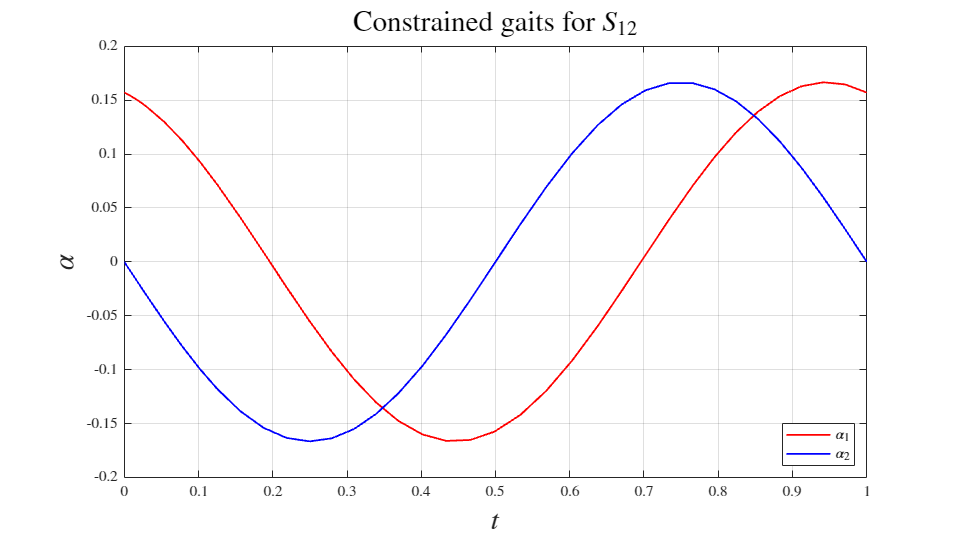

% Rescale the time vectors to end at 1 for the cycle
t = t/t(end); te = te/t(end);
% Plot the computed leg swings
figure('units','pixels','position',[0 0 1920 1080],'Color','w')
plot(t, y(:,1), 'r', 'linewidth', 1.2,'DisplayName','$\alpha_1$'); % alpha_1
hold on; grid on;
plot(t, y(:,2), 'b', 'linewidth', 1.2,'DisplayName','$\alpha_2$'); % alpha_2
% plot(te,ye,'ko','DisplayName','event trigger'); % plot the event trigger point
xlabel('$t$','Interpreter','latex',FontSize=20);
ylabel('$\alpha$','Interpreter','latex',FontSize=20);
title('Constrained gaits for $S_{12}$','Interpreter','latex',FontSize=20);
legend('location','southeast','Interpreter','latex',FontSize=10);

This is great! But, note that this is a numerical approximation and in order to find the **fixed phase between the shape elements**, let's do a sinusoidal fit as shown below,


$$s_1\sin{\left(2 \pi \left(t + \frac{1}{s_2} \right) \right)} + s_3 \\
s_1: \text{amplitude} \\
\frac{2 \pi}{s_2}: \text{phase offset} \\
s_3: \text{DC offset}$$


Each of the parameters above will be estimated for each shape-slice. Note, $s_3$ should be close to 0 in the estimation process (at least for the $S_{12}$ case).

s1 = sinefit(t,y(:,1))

s1 =     0.1666
   -1.4368
    0.0000


s2 = sinefit(t,y(:,2))

s2 =    -0.1666
   -1.0000
   -0.0000


Before we move on to the next, step; let's overlay the fits and see how the compare,

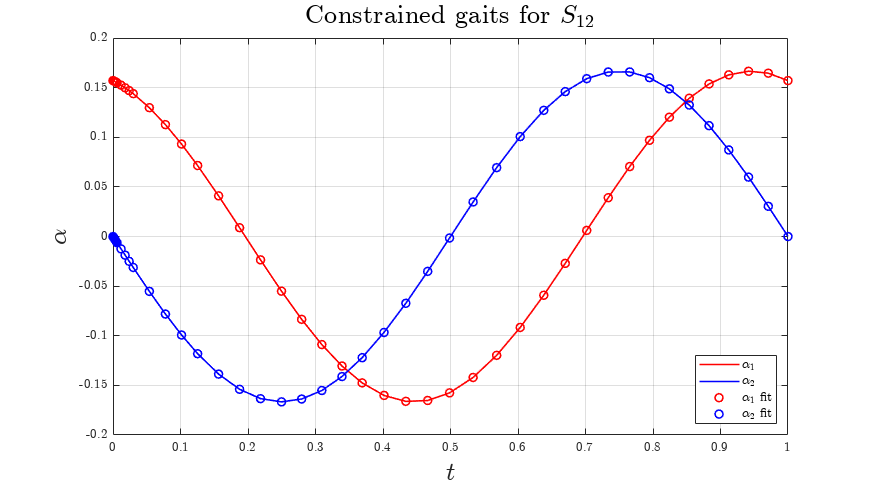

% Let's recreate the fit function
sfit = @(b,x)  b(1).*(sin(2*pi*x + 2*pi/b(2))) + b(3);
% Compute the fit with the time vector
y1 = sfit(s1,t); y2 = sfit(s2,t);
% Recreate the plot
figure('units','pixels','position',[0 0 1920 1080],'Color','w')
plot(t, y(:,1), 'r', 'linewidth', 1.2,'DisplayName','$\alpha_1$'); % alpha_1
hold on; grid on;
plot(t, y(:,2), 'b', 'linewidth', 1.2,'DisplayName','$\alpha_2$'); % alpha_2
plot(t, y1, 'ro', 'linewidth', 1.2,'DisplayName','$\alpha_1$ fit'); % alpha_1
plot(t, y2, 'bo', 'linewidth', 1.2,'DisplayName','$\alpha_2$ fit'); % alpha_2
xlabel('$t$','Interpreter','latex',FontSize=20);
ylabel('$\alpha$','Interpreter','latex',FontSize=20);
title('Constrained gaits for $S_{12}$','Interpreter','latex',FontSize=20);
legend('location','southeast','Interpreter','latex',FontSize=10);

The fit is perfect! Now, we just have to remove the time-dependence and plot it in the corresponding 2-element shape slice. Let's overlay this on top of the iso-$k^2$ surface plot that we did in the last section.

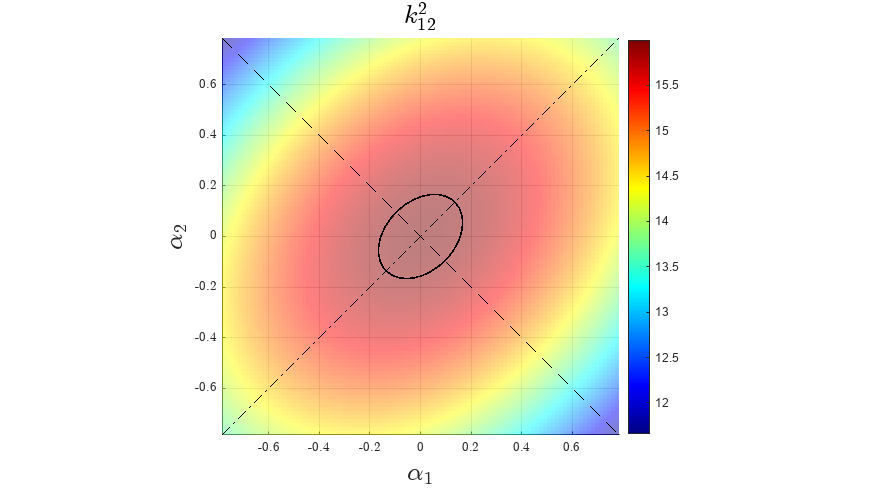

dnum = 100;                
xx = linspace(-ank,ank,dnum);          
yy = xx;
[a1,a2] = meshgrid(xx,yy);
ksq_sweep = ksq_12_func(0, aa, ll, a1, a2);
ksq_M = ksq_12_func(0, aa, ll, xx, yy);
ksq_m = ksq_12_func(0, aa, ll, xx, -yy);
% ksq_x = ksq_12_func(0, aa, ll, xx, 0*yy);
% ksq_y = ksq_12_func(0, aa, ll, 0*xx, yy);
ksq_phi = ksq_12_func(0, aa, ll, y1, y2);
figure('units','pixels','position',[0 0 1920 1080],'Color','w')
surf(a1,a2,ksq_sweep,'EdgeColor','none','FaceAlpha',0.5); % 50% transparency
axis equal tight tight; hold on; view(2);
colormap(jet);
colorbar();
line(xx,yy,ksq_M,'Color','k','LineStyle','-.');
line(xx,-yy,ksq_m,'Color','k','LineStyle','--');
% line(0*xx,yy,ksq_y,'Color','k','LineStyle',':');
% line(xx,0*yy,ksq_x,'Color','k','LineStyle',':');
line(y1,y2,ksq_phi,'Color', 'k','LineStyle','-', 'LineWidth', 1.2); % constrained gait trajectory
xlabel('$\alpha_1$','Interpreter','latex',FontSize=20);
ylabel('$\alpha_2$','Interpreter','latex',FontSize=20);
title('$k^2_{12}$','Interpreter','latex',FontSize=20);

With further investgation, we can see that this doesn't work very well in the ispi-lateral legs case since the attracter is not at the origin of the shape-space slice. Let's abandon this curve-fitting framework for now.

#### Iso-$k^2$ contours and flow

The goal here is to take a vector field based approach to modeling the $k^2$ level-sets and analyze the saddle and center behavior exhibited by our fitted curve.

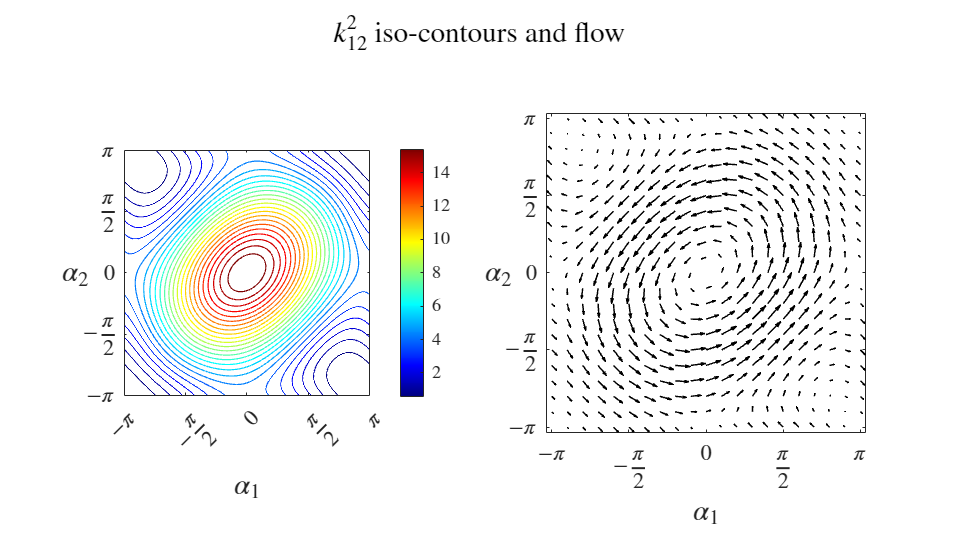

% Loading data and symbolic vars
load('case_1_kinematics');
syms a l real positive % syms tau real
assume(a<=1);
syms alpha_1 alpha_2 alpha_3 alpha_4 theta real
rot_in_ij = [cos(theta), -sin(theta);
            sin(theta), cos(theta)];
rot_in_ij = matlabFunction(rot_in_ij, 'Vars', theta);

% Conside the S12 submanifold info
ksq = matlabFunction(ksq_12,'Vars',[a, l, alpha_1, alpha_2]);
dphi_12 = simplify(round(rot_in_ij(-pi/2))*[diff(ksq_12,alpha_1) diff(ksq_12,alpha_2)]','Steps',10);
dphi_x_magscaled = [1,0]*dphi_12; dphi_y_magscaled = [0,1]*dphi_12;
dphi_x_magscaled = matlabFunction(dphi_x_magscaled,'Vars',[a, l, alpha_1, alpha_2]);
dphi_y_magscaled = matlabFunction(dphi_y_magscaled,'Vars',[a, l, alpha_1, alpha_2]);

% Plotting function
plot_ksq_isocontflow(ksq,dphi_x_magscaled,dphi_y_magscaled,1,2);

This is great! Let's abandon the gait constraint and switching line approaches. Instead we shall choose to remain on the level-sets using the local flow information and then define that an infinitesimal $\phi_{ij}$-slice is obtained by flowing along $-d\phi_{ij}$ in swing phase and $+d\phi_{ij}$ (showing in the iso-$k^2$ flow plot above) in the stance phase. But, there is one more change to make-- the flow vector fields seem to be scaled by the gradient magnitude, but we only need(/care about) the direction for generating stratified panels. Let's also look at this stuff for an ispi-lateral submanifold (say $S_{23}$) and alternating submanifold (say $S_{24}$).

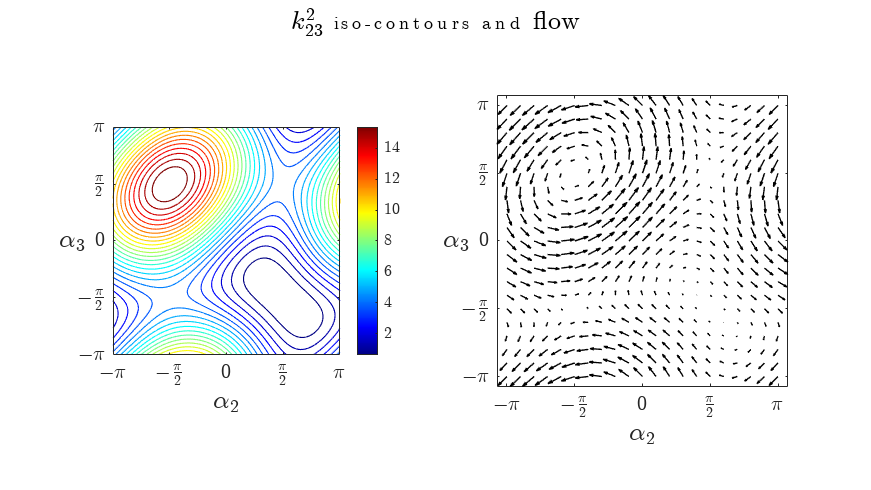

%---------------------------------------------------------------------------------------------------
ksq = matlabFunction(ksq_23,'Vars',[a, l, alpha_2, alpha_3]);
dphi_23 = simplify(round(rot_in_ij(-pi/2))*[diff(ksq_23,alpha_2) diff(ksq_23,alpha_3)]','Steps',10);
dphi_x_magscaled = [1,0]*dphi_23; dphi_y_magscaled = [0,1]*dphi_23;
dphi_x_magscaled = matlabFunction(dphi_x_magscaled,'Vars',[a, l, alpha_2, alpha_3]); 
dphi_y_magscaled = matlabFunction(dphi_y_magscaled,'Vars',[a, l, alpha_2, alpha_3]);
plot_ksq_isocontflow(ksq,dphi_x_magscaled,dphi_y_magscaled,2,3);

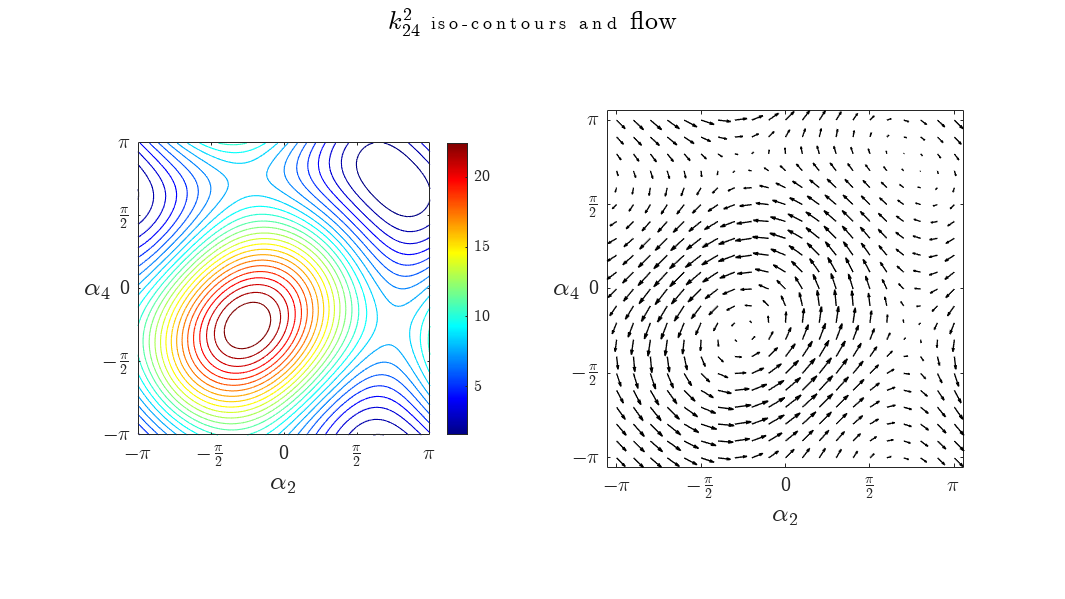

%---------------------------------------------------------------------------------------------------
ksq = matlabFunction(ksq_24,'Vars',[a, l, alpha_2, alpha_4]);
dphi_24 = simplify(round(rot_in_ij(-pi/2))*[diff(ksq_24,alpha_2) diff(ksq_24,alpha_4)]','Steps',10);
dphi_x_magscaled = [1,0]*dphi_24; dphi_y_magscaled = [0,1]*dphi_24;
dphi_x_magscaled = matlabFunction(dphi_x_magscaled,'Vars',[a, l, alpha_2, alpha_4]); 
dphi_y_magscaled = matlabFunction(dphi_y_magscaled,'Vars',[a, l, alpha_2, alpha_4]);
plot_ksq_isocontflow(ksq,dphi_x_magscaled,dphi_y_magscaled,2,4);

#### Kinematics Structure -- Gait constraints

Now, we have everything to proceed towards the analysis of connection vector fields for the case 1 system. As a final step, let's pack all of these results in the kinematic structure.

% Loading data and symbolic vars
load('case_1_kinematics');
syms a l real positive
assume(a<=1);
syms alpha_1 alpha_2 alpha_3 alpha_4 theta real
rot_in_ij = [cos(theta), -sin(theta);
            sin(theta), cos(theta)];
rot_in_ij = matlabFunction(rot_in_ij, 'Vars', theta);

% Pack the information into a kinematic strcture and save it in the
% case_1_kinematics.mat file ----------------------------------------------
kin = [];
kin.ksq_ij{1} = matlabFunction(ksq_12,'Vars',[a, l, alpha_1, alpha_2]);
kin.ksq_ij{2} = matlabFunction(ksq_23,'Vars',[a, l, alpha_2, alpha_3]);
kin.ksq_ij{3} = matlabFunction(ksq_34,'Vars',[a, l, alpha_3, alpha_4]);
kin.ksq_ij{4} = matlabFunction(ksq_41,'Vars',[a, l, alpha_4, alpha_1]);
kin.ksq_ij{5} = matlabFunction(ksq_13,'Vars',[a, l, alpha_1, alpha_3]);
kin.ksq_ij{6} = matlabFunction(ksq_24,'Vars',[a, l, alpha_2, alpha_4]);

%------------------------------------ gradient-scaled, iso-ksq flow vector
dphi_12 = simplify(round(rot_in_ij(-pi/2))*[diff(ksq_12,alpha_1) diff(ksq_12,alpha_2)]','Steps',10); % S12
kin.dphi_ij{1} = dphi_12;
kin.dphi_ij_s_vector{1} = matlabFunction(dphi_12,'Vars',[a, l, alpha_1, alpha_2]); 
dphi_23 = simplify(round(rot_in_ij(-pi/2))*[diff(ksq_23,alpha_2) diff(ksq_23,alpha_3)]','Steps',10); % S23
kin.dphi_ij{2} = dphi_23;
kin.dphi_ij_s_vector{2} = matlabFunction(dphi_23,'Vars',[a, l, alpha_2, alpha_3]); 
dphi_34 = simplify(round(rot_in_ij(-pi/2))*[diff(ksq_34,alpha_3) diff(ksq_34,alpha_4)]','Steps',10); % S34
kin.dphi_ij{3} = dphi_34;
kin.dphi_ij_s_vector{3} = matlabFunction(dphi_34,'Vars',[a, l, alpha_3, alpha_4]); 
dphi_41 = simplify(round(rot_in_ij(-pi/2))*[diff(ksq_41,alpha_4) diff(ksq_41,alpha_1)]','Steps',10); % S41
kin.dphi_ij{4} = dphi_41;
kin.dphi_ij_s_vector{4} = matlabFunction(dphi_41,'Vars',[a, l, alpha_4, alpha_1]); 
dphi_13 = simplify(round(rot_in_ij(-pi/2))*[diff(ksq_13,alpha_1) diff(ksq_13,alpha_3)]','Steps',10); % S13
kin.dphi_ij{5} = dphi_13;
kin.dphi_ij_s_vector{5} = matlabFunction(dphi_13,'Vars',[a, l, alpha_1, alpha_3]); 
dphi_24 = simplify(round(rot_in_ij(-pi/2))*[diff(ksq_24,alpha_2) diff(ksq_24,alpha_4)]','Steps',10); % S24
kin.dphi_ij{6} = dphi_24;
kin.dphi_ij_s_vector{6} = matlabFunction(dphi_24,'Vars',[a, l, alpha_2, alpha_4]);

%------------------------------------ gradient-scaled, iso-ksq flow elements (square-root for panels!)
dphi_12 = simplify(round(rot_in_ij(-pi/2))*[diff(ksq_12,alpha_1) diff(ksq_12,alpha_2)]','Steps',10); % S12
dphi_x = [1,0]*dphi_12; dphi_y = [0,1]*dphi_12;
kin.dphi_ij_s{1,1} = matlabFunction(dphi_x,'Vars',[a, l, alpha_1, alpha_2]); 
kin.dphi_ij_s{1,2} = matlabFunction(dphi_y,'Vars',[a, l, alpha_1, alpha_2]);
dphi_23 = simplify(round(rot_in_ij(-pi/2))*[diff(ksq_23,alpha_2) diff(ksq_23,alpha_3)]','Steps',10); % S23
dphi_x = [1,0]*dphi_23; dphi_y = [0,1]*dphi_23;
kin.dphi_ij_s{2,1} = matlabFunction(dphi_x,'Vars',[a, l, alpha_2, alpha_3]); 
kin.dphi_ij_s{2,2} = matlabFunction(dphi_y,'Vars',[a, l, alpha_2, alpha_3]);
dphi_34 = simplify(round(rot_in_ij(-pi/2))*[diff(ksq_34,alpha_3) diff(ksq_34,alpha_4)]','Steps',10); % S34
dphi_x = [1,0]*dphi_34; dphi_y = [0,1]*dphi_34;
kin.dphi_ij_s{3,1} = matlabFunction(dphi_x,'Vars',[a, l, alpha_3, alpha_4]); 
kin.dphi_ij_s{3,2} = matlabFunction(dphi_y,'Vars',[a, l, alpha_3, alpha_4]);
dphi_41 = simplify(round(rot_in_ij(-pi/2))*[diff(ksq_41,alpha_4) diff(ksq_41,alpha_1)]','Steps',10); % S41
dphi_x = [1,0]*dphi_41; dphi_y = [0,1]*dphi_41;
kin.dphi_ij_s{4,1} = matlabFunction(dphi_x,'Vars',[a, l, alpha_4, alpha_1]); 
kin.dphi_ij_s{4,2} = matlabFunction(dphi_y,'Vars',[a, l, alpha_4, alpha_1]);
dphi_13 = simplify(round(rot_in_ij(-pi/2))*[diff(ksq_13,alpha_1) diff(ksq_13,alpha_3)]','Steps',10); % S13
dphi_x = [1,0]*dphi_13; dphi_y = [0,1]*dphi_13;
kin.dphi_ij_s{5,1} = matlabFunction(dphi_x,'Vars',[a, l, alpha_1, alpha_3]); 
kin.dphi_ij_s{5,2} = matlabFunction(dphi_y,'Vars',[a, l, alpha_1, alpha_3]);
dphi_24 = simplify(round(rot_in_ij(-pi/2))*[diff(ksq_24,alpha_2) diff(ksq_24,alpha_4)]','Steps',10); % S24
dphi_x = [1,0]*dphi_24; dphi_y = [0,1]*dphi_24;
kin.dphi_ij_s{6,1} = matlabFunction(dphi_x,'Vars',[a, l, alpha_2, alpha_4]); 
kin.dphi_ij_s{6,2} = matlabFunction(dphi_y,'Vars',[a, l, alpha_2, alpha_4]);

%------------------------------------ connection vector fields, element-wise
Ax_1_12 = A_1_12(1,1); Ax_2_12 = A_1_12(1,2); % S12
Ay_1_12 = A_1_12(2,1); Ay_2_12 = A_1_12(2,2);
Atheta_1_12 = A_1_12(3,1); Atheta_2_12 = A_1_12(3,2);
kin.Ax_ij{1} = {Ax_1_12, Ax_2_12};
kin.Ay_ij{1} = {Ay_1_12, Ay_2_12};
kin.Atheta_ij{1} = {Atheta_1_12, Atheta_2_12};
Ax_1_23 = A_1_23(1,2); Ax_2_23 = A_1_23(1,3); % S23
Ay_1_23 = A_1_23(2,2); Ay_2_23 = A_1_23(2,3);
Atheta_1_23 = A_1_23(3,2); Atheta_2_23 = A_1_23(3,3);
kin.Ax_ij{2} = {Ax_1_23, Ax_2_23};
kin.Ay_ij{2} = {Ay_1_23, Ay_2_23};
kin.Atheta_ij{2} = {Atheta_1_23, Atheta_2_23};
Ax_1_34 = A_1_34(1,3); Ax_2_34 = A_1_34(1,4); % S34
Ay_1_34 = A_1_34(2,3); Ay_2_34 = A_1_34(2,4);
Atheta_1_34 = A_1_34(3,3); Atheta_2_34 = A_1_34(3,4);
kin.Ax_ij{3} = {Ax_1_34, Ax_2_34};
kin.Ay_ij{3} = {Ay_1_34, Ay_2_34};
kin.Atheta_ij{3} = {Atheta_1_34, Atheta_2_34};
Ax_1_41 = A_1_41(1,4); Ax_2_41 = A_1_41(1,1); % S41
Ay_1_41 = A_1_41(2,4); Ay_2_41 = A_1_41(2,1);
Atheta_1_41 = A_1_41(3,4); Atheta_2_41 = A_1_41(3,1);
kin.Ax_ij{4} = {Ax_1_41, Ax_2_41};
kin.Ay_ij{4} = {Ay_1_41, Ay_2_41};
kin.Atheta_ij{4} = {Atheta_1_41, Atheta_2_41};
Ax_1_13 = A_1_13(1,1); Ax_2_13 = A_1_13(1,3); % S13
Ay_1_13 = A_1_13(2,1); Ay_2_13 = A_1_13(2,3);
Atheta_1_13 = A_1_13(3,1); Atheta_2_13 = A_1_13(3,3);
kin.Ax_ij{5} = {Ax_1_13, Ax_2_13};
kin.Ay_ij{5} = {Ay_1_13, Ay_2_13};
kin.Atheta_ij{5} = {Atheta_1_13, Atheta_2_13};
Ax_1_24 = A_1_24(1,2); Ax_2_24 = A_1_24(1,4); % S24
Ay_1_24 = A_1_24(2,2); Ay_2_24 = A_1_24(2,4);
Atheta_1_24 = A_1_24(3,2); Atheta_2_24 = A_1_24(3,4);
kin.Ax_ij{6} = {Ax_1_24, Ax_2_24};
kin.Ay_ij{6} = {Ay_1_24, Ay_2_24};
kin.Atheta_ij{6} = {Atheta_1_24, Atheta_2_24};

% Save
save('case_1_kinematics.mat','kin','-append');

% Clear everything after writing information
clear all; close all; clc;

#### Analytical Total lie-bracket or Generalized Curl

Before we move towards analysis of the connection vector field and the generation of stratified panels, it is good to set up the symbolic machinery to compute those quantities. The following papers were referred to create the symbolic functions shown in this section,

1) [https://link.springer.com/article/10.1140/epjst/e2015-50085-y](https://link.springer.com/article/10.1140/epjst/e2015-50085-y) -- nonconservativity and noncommutativity in locomotion; **equation C.3 and C.4**

2) [https://ieeexplore.ieee.org/abstract/document/8758237](https://ieeexplore.ieee.org/abstract/document/8758237) -- geometry of optimal gaits for drag-dominated kinematic systems; **equation 12**

3) [https://ieeexplore.ieee.org/abstract/document/9774857](https://ieeexplore.ieee.org/abstract/document/9774857) -- geometry of optimal gaits for inertia-dominated kinematic systems; **equation 12**

**The total lie-bracket of the connection vector field is approximated linearly as the sum of the exterior derivative and first order lie bracket,**


$$D(-\mathbf{A}) = -d\mathbf{A} + [\mathbf{A}_1 \, , \, \mathbf{A}_2]$$


We shall compute the components and finally get the generalized curl.

% Load data and initialize vars for just S12
load('case_1_kinematics');
syms a l real positive
assume(a<=1);
syms alpha_1 alpha_2 real

% Create the connection we shall analyze
A = A_1_12(:,1:2)

% Separate the connection into components
A_1__x = A(1,1); A_1__y = A(2,1); A_1__theta = A(3,1);
A_2__x = A(1,2); A_2__y = A(2,2); A_2__theta = A(3,2);
% Compute the exterior derivative, and separate into components
mdA = -simplify(diff(A(:,1),alpha_2) - diff(A(:,2),alpha_1), 'Steps', 50)

$$mdA = \left(\begin{array}{c} -a^{2}\,l^{3}\,\left(\sin\left(\alpha_{1}+\alpha_{2}\right)-a\,\cos\left(\alpha_{1}\right)+a\,\cos\left(\alpha_{2}\right)\right)\\ -a^{2}\,l^{3}\,\left(2\,\sin\left(\alpha_{1}\right)\,\sin\left(\alpha_{2}\right)-a\,\sin\left(\alpha_{1}\right)+a\,\sin\left(\alpha_{2}\right)+\cos\left(\alpha_{1}\right)\,\sin\left(\alpha_{2}\right)-\cos\left(\alpha_{2}\right)\,\sin\left(\alpha_{1}\right)\right)\\ 2\,a^{2}\,l^{4}\,\left(2\,\sin\left(\alpha_{1}+\alpha_{2}\right)-a\,\cos\left(\alpha_{1}\right)+a\,\cos\left(\alpha_{2}\right)+a\,\sin\left(\alpha_{1}\right)+a\,\sin\left(\alpha_{2}\right)\right) \end{array}\right)$$

% Compute the first order lie-bracket, and separate into components
lb_A = simplify([A_1__y*A_2__theta - A_2__y*A_1__theta;
                   A_2__x*A_1__theta - A_1__x*A_2__theta;
                   0],'Steps',50)

% Finally add the exterior derivative and lie-bracket to obtain the
% generalized curl or total lie-bracket; split it component-wise.
simplify(mdA + lb_A,'Steps',50)

This is great! Now, let's compute this for each submanifold and store it in the kinematics structure.

#### Kinematics Structure -- Total lie-bracket $D(-\mathbf{A})$

% Loading data and symbolic vars
load('case_1_kinematics');
syms a l real positive
assume(a<=1);
syms alpha_1 alpha_2 alpha_3 alpha_4 real

% Simplification steps ---------------------------------------------
stp = 30;
%------------------------------------ Total lie-bracket element-wise
A = A_1_12(:,1:2); i = 1; % S12
A_1__x = A(1,1); A_1__y = A(2,1); A_1__theta = A(3,1);
A_2__x = A(1,2); A_2__y = A(2,2); A_2__theta = A(3,2);
mdA = -simplify(diff(A(:,1),alpha_2) - diff(A(:,2),alpha_1), 'Steps', stp);
mdA_x = mdA(1); mdA_y = mdA(2); mdA_theta = mdA(3);
lb_A = simplify([A_1__y*A_2__theta - A_2__y*A_1__theta;
                   A_2__x*A_1__theta - A_1__x*A_2__theta;
                   0],'Steps',stp);
lb_A_x = lb_A(1); lb_A_y = lb_A(2); lb_A_theta = lb_A(3);
D_mA = simplify(mdA + lb_A,'Steps',stp);
D_mA_x = D_mA(1); D_mA_y = D_mA(2); D_mA_theta = D_mA(3);
kin.mdA_x{i} = mdA_x; kin.mdA_y{i} = mdA_y; kin.mdA_theta{i} = mdA_theta; % save
kin.lb_A_x{i} = lb_A_x; kin.lb_A_y{i} = lb_A_y; kin.lb_A_theta{i} = lb_A_theta;
kin.D_mA_x{i} = D_mA_x; kin.D_mA_y{i} = D_mA_y; kin.D_mA_theta{i} = D_mA_theta;
A = A_1_23(:,2:3); i = 2; % S23
A_1__x = A(1,1); A_1__y = A(2,1); A_1__theta = A(3,1);
A_2__x = A(1,2); A_2__y = A(2,2); A_2__theta = A(3,2);
mdA = -simplify(diff(A(:,1),alpha_3) - diff(A(:,2),alpha_2), 'Steps', stp);
mdA_x = mdA(1); mdA_y = mdA(2); mdA_theta = mdA(3);
lb_A = simplify([A_1__y*A_2__theta - A_2__y*A_1__theta;
                   A_2__x*A_1__theta - A_1__x*A_2__theta;
                   0],'Steps',stp);
lb_A_x = lb_A(1); lb_A_y = lb_A(2); lb_A_theta = lb_A(3);
D_mA = simplify(mdA + lb_A,'Steps',stp);
D_mA_x = D_mA(1); D_mA_y = D_mA(2); D_mA_theta = D_mA(3);
kin.mdA_x{i} = mdA_x; kin.mdA_y{i} = mdA_y; kin.mdA_theta{i} = mdA_theta;
kin.lb_A_x{i} = lb_A_x; kin.lb_A_y{i} = lb_A_y; kin.lb_A_theta{i} = lb_A_theta;
kin.D_mA_x{i} = D_mA_x; kin.D_mA_y{i} = D_mA_y; kin.D_mA_theta{i} = D_mA_theta;
A = A_1_34(:,3:4); i = 3; % S34
A_1__x = A(1,1); A_1__y = A(2,1); A_1__theta = A(3,1);
A_2__x = A(1,2); A_2__y = A(2,2); A_2__theta = A(3,2);
mdA = -simplify(diff(A(:,1),alpha_4) - diff(A(:,2),alpha_3), 'Steps', stp);
mdA_x = mdA(1); mdA_y = mdA(2); mdA_theta = mdA(3);
lb_A = simplify([A_1__y*A_2__theta - A_2__y*A_1__theta;
                   A_2__x*A_1__theta - A_1__x*A_2__theta;
                   0],'Steps',stp);
lb_A_x = lb_A(1); lb_A_y = lb_A(2); lb_A_theta = lb_A(3);
D_mA = simplify(mdA + lb_A,'Steps',stp);
D_mA_x = D_mA(1); D_mA_y = D_mA(2); D_mA_theta = D_mA(3);
kin.mdA_x{i} = mdA_x; kin.mdA_y{i} = mdA_y; kin.mdA_theta{i} = mdA_theta;
kin.lb_A_x{i} = lb_A_x; kin.lb_A_y{i} = lb_A_y; kin.lb_A_theta{i} = lb_A_theta;
kin.D_mA_x{i} = D_mA_x; kin.D_mA_y{i} = D_mA_y; kin.D_mA_theta{i} = D_mA_theta;
A = [A_1_41(:,4),A_1_41(:,1)]; i = 4; % S41
A_1__x = A(1,1); A_1__y = A(2,1); A_1__theta = A(3,1);
A_2__x = A(1,2); A_2__y = A(2,2); A_2__theta = A(3,2);
mdA = -simplify(diff(A(:,1),alpha_1) - diff(A(:,2),alpha_4), 'Steps', stp);
mdA_x = mdA(1); mdA_y = mdA(2); mdA_theta = mdA(3);
lb_A = simplify([A_1__y*A_2__theta - A_2__y*A_1__theta;
                   A_2__x*A_1__theta - A_1__x*A_2__theta;
                   0],'Steps',stp);
lb_A_x = lb_A(1); lb_A_y = lb_A(2); lb_A_theta = lb_A(3);
D_mA = simplify(mdA + lb_A,'Steps',stp);
D_mA_x = D_mA(1); D_mA_y = D_mA(2); D_mA_theta = D_mA(3);
kin.mdA_x{i} = mdA_x; kin.mdA_y{i} = mdA_y; kin.mdA_theta{i} = mdA_theta;
kin.lb_A_x{i} = lb_A_x; kin.lb_A_y{i} = lb_A_y; kin.lb_A_theta{i} = lb_A_theta;
kin.D_mA_x{i} = D_mA_x; kin.D_mA_y{i} = D_mA_y; kin.D_mA_theta{i} = D_mA_theta;
A = [A_1_13(:,1),A_1_13(:,3)]; i = 5; % S13
A_1__x = A(1,1); A_1__y = A(2,1); A_1__theta = A(3,1);
A_2__x = A(1,2); A_2__y = A(2,2); A_2__theta = A(3,2);
mdA = -simplify(diff(A(:,1),alpha_3) - diff(A(:,2),alpha_1), 'Steps', stp);
mdA_x = mdA(1); mdA_y = mdA(2); mdA_theta = mdA(3);
lb_A = simplify([A_1__y*A_2__theta - A_2__y*A_1__theta;
                   A_2__x*A_1__theta - A_1__x*A_2__theta;
                   0],'Steps',stp);
lb_A_x = lb_A(1); lb_A_y = lb_A(2); lb_A_theta = lb_A(3);
D_mA = simplify(mdA + lb_A,'Steps',stp);
D_mA_x = D_mA(1); D_mA_y = D_mA(2); D_mA_theta = D_mA(3);
kin.mdA_x{i} = mdA_x; kin.mdA_y{i} = mdA_y; kin.mdA_theta{i} = mdA_theta;
kin.lb_A_x{i} = lb_A_x; kin.lb_A_y{i} = lb_A_y; kin.lb_A_theta{i} = lb_A_theta;
kin.D_mA_x{i} = D_mA_x; kin.D_mA_y{i} = D_mA_y; kin.D_mA_theta{i} = D_mA_theta;
A = [A_1_24(:,2),A_1_24(:,4)]; i = 6; % S24
A_1__x = A(1,1); A_1__y = A(2,1); A_1__theta = A(3,1);
A_2__x = A(1,2); A_2__y = A(2,2); A_2__theta = A(3,2);
mdA = -simplify(diff(A(:,1),alpha_4) - diff(A(:,2),alpha_2), 'Steps', stp);
mdA_x = mdA(1); mdA_y = mdA(2); mdA_theta = mdA(3);
lb_A = simplify([A_1__y*A_2__theta - A_2__y*A_1__theta;
                   A_2__x*A_1__theta - A_1__x*A_2__theta;
                   0],'Steps',stp);
lb_A_x = lb_A(1); lb_A_y = lb_A(2); lb_A_theta = lb_A(3);
D_mA = simplify(mdA + lb_A,'Steps',stp);
D_mA_x = D_mA(1); D_mA_y = D_mA(2); D_mA_theta = D_mA(3);
kin.mdA_x{i} = mdA_x; kin.mdA_y{i} = mdA_y; kin.mdA_theta{i} = mdA_theta;
kin.lb_A_x{i} = lb_A_x; kin.lb_A_y{i} = lb_A_y; kin.lb_A_theta{i} = lb_A_theta;
kin.D_mA_x{i} = D_mA_x; kin.D_mA_y{i} = D_mA_y; kin.D_mA_theta{i} = D_mA_theta;

% Save
save('case_1_kinematics.mat','kin','-append');

% Clear everything after writing information
clear all; close all; clc;

#### Analytical Stratified Panels

Here, we compute the analytical version of the stratified panels. An infinitesimal gait in the $ij^{th}$ shape-space slice is defined as swinging along $-d\phi_{ij}$ and stancing along $+d\phi_{ij}$. Hence, we simply compute this multiplying the connection dual with the shape-space velocity (is independent of time for a connection based model).

% Load data and initialize vars for just S12
load('case_1_kinematics');
syms a l real positive
assume(a<=1);
syms alpha_1 alpha_2 real

% Get the connection and gait constraint
A = A_1_12(:,1:2)

dphi_unit = kin.dphi_ij{1}/norm(kin.dphi_ij{1})

$$dphi\_unit = \begin{array}{l} \left(\begin{array}{c} -\frac{2\,a\,l^{2}\,\left(2\,\sin\left(\alpha_{2}\right)-a\,\sin\left(\alpha_{1}-\alpha_{2}\right)\right)}{\sigma_{1}}\\ \frac{2\,a\,l^{2}\,\left(2\,\sin\left(\alpha_{1}\right)+a\,\sin\left(\alpha_{1}-\alpha_{2}\right)\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{4\,l^{4}\,{\left|a\,\left(2\,\sin\left(\alpha_{1}\right)+a\,\sin\left(\alpha_{1}-\alpha_{2}\right)\right)\right|}^{2}+4\,l^{4}\,{\left|a\,\left(2\,\sin\left(\alpha_{2}\right)-a\,\sin\left(\alpha_{1}-\alpha_{2}\right)\right)\right|}^{2}} \end{array}$$

% Compute the stratified panel (just multiply them)
simplify(A*dphi_unit,'Steps',50)

Alright, let's compute this and package it for each submanifold.

#### Kinematics Structure -- Stratified Panels $dz_\phi$

% Loading data and symbolic vars
load('case_1_kinematics');
syms a l real positive
assume(a<=1);
syms alpha_1 alpha_2 alpha_3 alpha_4 real

stp = 50;
%------------------------------------ Stratified panels element-wise
i = 1;
A = A_1_12(:,1:2);                     % S12
dphi = kin.dphi_ij{i}/norm(kin.dphi_ij{i});
dz_phi = -simplify(A*dphi,'Steps',stp);
kin.dz_phi{i} = dz_phi;
kin.dz_phi_x{i} = matlabFunction(dz_phi(1),'Vars',[a, l, alpha_1, alpha_2]);
kin.dz_phi_y{i} = matlabFunction(dz_phi(2),'Vars',[a, l, alpha_1, alpha_2]);
kin.dz_phi_theta{i} = matlabFunction(dz_phi(3),'Vars',[a, l, alpha_1, alpha_2]);
i = 2;
A = A_1_23(:,2:3);                     % S23
dphi = kin.dphi_ij{i}/norm(kin.dphi_ij{i});
dz_phi = -simplify(A*dphi,'Steps',stp);
kin.dz_phi{i} = dz_phi;
kin.dz_phi_x{i} = matlabFunction(dz_phi(1),'Vars',[a, l, alpha_2, alpha_3]);
kin.dz_phi_y{i} = matlabFunction(dz_phi(2),'Vars',[a, l, alpha_2, alpha_3]);
kin.dz_phi_theta{i} = matlabFunction(dz_phi(3),'Vars',[a, l, alpha_2, alpha_3]);
i = 3;
A = A_1_34(:,3:4);                     % S34
dphi = kin.dphi_ij{i}/norm(kin.dphi_ij{i});
dz_phi = -simplify(A*dphi,'Steps',stp);
kin.dz_phi{i} = dz_phi;
kin.dz_phi_x{i} = matlabFunction(dz_phi(1),'Vars',[a, l, alpha_3, alpha_4]);
kin.dz_phi_y{i} = matlabFunction(dz_phi(2),'Vars',[a, l, alpha_3, alpha_4]);
kin.dz_phi_theta{i} = matlabFunction(dz_phi(3),'Vars',[a, l, alpha_3, alpha_4]);
i = 4;
A = [A_1_41(:,4) A_1_41(:,1)];                     % S41
dphi = kin.dphi_ij{i}/norm(kin.dphi_ij{i});
dz_phi = -simplify(A*dphi,'Steps',stp);
kin.dz_phi{i} = dz_phi;
kin.dz_phi_x{i} = matlabFunction(dz_phi(1),'Vars',[a, l, alpha_4, alpha_1]);
kin.dz_phi_y{i} = matlabFunction(dz_phi(2),'Vars',[a, l, alpha_4, alpha_1]);
kin.dz_phi_theta{i} = matlabFunction(dz_phi(3),'Vars',[a, l, alpha_4, alpha_1]);
i = 5;
A = [A_1_13(:,1) A_1_13(:,3)];                     % S13
dphi = kin.dphi_ij{i}/norm(kin.dphi_ij{i});
dz_phi = -simplify(A*dphi,'Steps',stp);
kin.dz_phi{i} = dz_phi;
kin.dz_phi_x{i} = matlabFunction(dz_phi(1),'Vars',[a, l, alpha_1, alpha_3]);
kin.dz_phi_y{i} = matlabFunction(dz_phi(2),'Vars',[a, l, alpha_1, alpha_3]);
kin.dz_phi_theta{i} = matlabFunction(dz_phi(3),'Vars',[a, l, alpha_1, alpha_3]);
i = 6;
A = [A_1_24(:,2) A_1_24(:,4)];                     % S24
dphi = kin.dphi_ij{i}/norm(kin.dphi_ij{i});
dz_phi = -simplify(A*dphi,'Steps',stp);
kin.dz_phi{i} = dz_phi;
kin.dz_phi_x{i} = matlabFunction(dz_phi(1),'Vars',[a, l, alpha_2, alpha_4]);
kin.dz_phi_y{i} = matlabFunction(dz_phi(2),'Vars',[a, l, alpha_2, alpha_4]);
kin.dz_phi_theta{i} = matlabFunction(dz_phi(3),'Vars',[a, l, alpha_2, alpha_4]);

% Save
save('case_1_kinematics.mat','kin','-append');

% Clear everything after writing information
clear all; close all; clc;

#### Connection vector fields, Generalized curl, and Stratified panels of the level-2 submanifolds

Consider $S_{12}$ as a first step; once we have a plot, we can automate the process later.

% Load data and initialize vars -------------------------------------------
load('case_1_kinematics');
syms a l real positive
assume(a<=1);
syms alpha_1 alpha_2 alpha_3 alpha_4 real

% -------------------------------------------------------------------------
% -------------------------------------------------------------------------
i = 1;
% ksq ---------------------------------------------------------------------
ksq = kin.ksq_ij{i};
% connection --------------------------------------------------------------
A_x__1 = matlabFunction(kin.Ax_ij{i}{1,1},'Vars',[a, l, alpha_1, alpha_2]);
A_x__2 = matlabFunction(kin.Ax_ij{i}{1,2},'Vars',[a, l, alpha_1, alpha_2]);
A_y__1 = matlabFunction(kin.Ay_ij{i}{1,1},'Vars',[a, l, alpha_1, alpha_2]); 
A_y__2 = matlabFunction(kin.Ay_ij{i}{1,2},'Vars',[a, l, alpha_1, alpha_2]);
A_theta__1 = matlabFunction(kin.Atheta_ij{i}{1,1},'Vars',[a, l, alpha_1, alpha_2]); 
A_theta__2 = matlabFunction(kin.Atheta_ij{i}{1,2},'Vars',[a, l, alpha_1, alpha_2]);
% Get the level-sets info as well to visualize valid gaits ----------------
dphi_x = kin.dphi_ij_s{i,1}; dphi_y = kin.dphi_ij_s{i,2};
% get the curl ------------------------------------------------------------
mdA_x = matlabFunction(kin.mdA_x{i},'Vars',[a, l, alpha_1, alpha_2]);
mdA_y = matlabFunction(kin.mdA_y{i},'Vars',[a, l, alpha_1, alpha_2]);
mdA_theta = matlabFunction(kin.mdA_theta{i},'Vars',[a, l, alpha_1, alpha_2]);
lb_A_x = matlabFunction(kin.lb_A_x{i},'Vars',[a, l, alpha_1, alpha_2]);
lb_A_y = matlabFunction(kin.lb_A_y{i},'Vars',[a, l, alpha_1, alpha_2]);
lb_A_theta = matlabFunction(kin.lb_A_theta{i},'Vars',[a, l, alpha_1, alpha_2]);
D_mA_x = matlabFunction(kin.D_mA_x{i},'Vars',[a, l, alpha_1, alpha_2]);
D_mA_y = matlabFunction(kin.D_mA_y{i},'Vars',[a, l, alpha_1, alpha_2]);
D_mA_theta = matlabFunction(kin.D_mA_theta{i},'Vars',[a, l, alpha_1, alpha_2]);
% stratified panel --------------------------------------------------------
dz_phi_x = kin.dz_phi_x{i};
dz_phi_y = kin.dz_phi_y{i};
dz_phi_theta = kin.dz_phi_theta{i};
% -------------------------------------------------------------------------
% -------------------------------------------------------------------------

% -------------------------------------------------------------------------
% parameters --------------------------------------------------------------
ank = pi;
aa = 1; ll = 1;
% Discretization ----------------------------------------------------------
dnum = 1001;
xx = linspace(-ank,ank,dnum);         
yy = xx;
[ai,aj] = meshgrid(xx,yy);
% Compute the scalar and vectors fields for display -----------------------
ksq_sweep = ksq(aa, ll, ai, aj);
if numel(ksq_sweep) == 1
    ksq_sweep = ksq_sweep*ones(size(ai));
end
A_x__1_sweep = A_x__1(aa, ll, ai, aj);
if numel(A_x__1_sweep) == 1
    A_x__1_sweep = A_x__1_sweep*ones(size(ai));
end
A_x__2_sweep = A_x__2(aa, ll, ai, aj);
if numel(A_x__2_sweep) == 1
    A_x__2_sweep = A_x__2_sweep*ones(size(ai));
end
A_y__1_sweep = A_y__1(aa, ll, ai, aj);
if numel(A_y__1_sweep) == 1
    A_y__1_sweep = A_y__1_sweep*ones(size(ai));
end
A_y__2_sweep = A_y__2(aa, ll, ai, aj);
if numel(A_y__2_sweep) == 1
    A_y__2_sweep = A_y__2_sweep*ones(size(ai));
end
A_theta__1_sweep = A_theta__1(aa, ll, ai, aj);
if numel(A_theta__1_sweep) == 1
    A_theta__1_sweep = A_theta__1_sweep*ones(size(ai));
end
A_theta__2_sweep = A_theta__2(aa, ll, ai, aj);
if numel(A_theta__2_sweep) == 1
    A_theta__2_sweep = A_theta__2_sweep*ones(size(ai));
end
u_sweep = dphi_x(aa, ll, ai, aj); % compute the iso-contour derivatives
if numel(u_sweep) == 1
    u_sweep = u_sweep*ones(size(ai));
end
v_sweep = dphi_y(aa, ll, ai, aj);
if numel(v_sweep) == 1
    v_sweep = v_sweep*ones(size(ai));
end
mdA_x_sweep = mdA_x(aa, ll, ai, aj); % compute the exterior derivative sweep
if numel(mdA_x_sweep) == 1
    mdA_x_sweep = mdA_x_sweep*ones(size(ai));
end
mdA_y_sweep = mdA_y(aa, ll, ai, aj);
if numel(mdA_y_sweep) == 1
    mdA_y_sweep = mdA_y_sweep*ones(size(ai));
end
mdA_theta_sweep = mdA_theta(aa, ll, ai, aj);
if numel(mdA_theta_sweep) == 1
    mdA_theta_sweep = mdA_theta_sweep*ones(size(ai));
end
lb_A_x_sweep = lb_A_x(aa, ll, ai, aj); % compute the first order lie-bracket
if numel(lb_A_x_sweep) == 1
    lb_A_x_sweep = lb_A_x_sweep*ones(size(ai));
end
lb_A_y_sweep = lb_A_y(aa, ll, ai, aj);
if numel(lb_A_y_sweep) == 1
    lb_A_y_sweep = lb_A_y_sweep*ones(size(ai));
end
lb_A_theta_sweep = lb_A_theta(aa, ll, ai, aj);
if numel(lb_A_theta_sweep) == 1
    lb_A_theta_sweep = lb_A_theta_sweep*ones(size(ai));
end
D_mA_x_sweep = D_mA_x(aa, ll, ai, aj); % compute the generalized curl
if numel(D_mA_x_sweep) == 1
    D_mA_x_sweep = D_mA_x_sweep*ones(size(ai));
end
D_mA_y_sweep = D_mA_y(aa, ll, ai, aj);
if numel(D_mA_y_sweep) == 1
    D_mA_y_sweep = D_mA_y_sweep*ones(size(ai));
end
D_mA_theta_sweep = D_mA_theta(aa, ll, ai, aj);
if numel(D_mA_theta_sweep) == 1
    D_mA_theta_sweep = D_mA_theta_sweep*ones(size(ai));
end
% stratified panels -------------------------------------------------------
dz_x_sweep = dz_phi_x(aa, ll, ai, aj);
if numel(dz_x_sweep) == 1
    dz_x_sweep = dz_x_sweep*ones(size(ai));
end
dz_y_sweep = dz_phi_y(aa, ll, ai, aj);
if numel(dz_y_sweep) == 1
    dz_y_sweep = dz_y_sweep*ones(size(ai));
end
dz_theta_sweep = dz_phi_theta(aa, ll, ai, aj);
if numel(dz_theta_sweep) == 1
    dz_theta_sweep = dz_theta_sweep*ones(size(ai));
end

% plot info ---------------------------------------------------------------
skipV = 75; % number of points to skip when plotting the vector field -- connection
sV = 100; % number of points to skip when plotting the vector field -- gait constraint
cLvl = 25; % number of contour levels
cfLvl = 100; % number of filled contour levels
gc_col = (1/255)*[215,25,28];
tickFS = 18; labelFS = 18; 
titleFS = 20; sgtitleFS = 20; % font sizes
cbarFS = 15;
fA = 1.00; % 0.50 % 1.00 % 0.40 % 0.75
lW_contour = (1.2*10)/cLvl; % contour linewidth scales with the number of countour lines
lW_Vector = (1.0/100)*skipV; % vector linewidth scales with the density of the vector field
lW_V = (0.35/100)*sV;
idxQ = 1:skipV:dnum; % indices to plot the connection vector field
iQ = 1:sV:dnum; % gait constraint vector fields
% -------------------------------------------------------------------------
% Set the default interpreter before plotting to latex
%%%% https://www.mathworks.com/matlabcentral/answers/346436-how-to-use-latex-interpreter-for-xticklabels
set(groot,'defaultAxesTickLabelInterpreter','latex'); 
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');
% -------------------------------------------------------------------------
% Custom colormap
CUB = flipud([159.3750,99.6030,63.4312;
          239.0625,149.4045,95.1469;
          255.0000,199.2060,126.8625;
            204,204,204;
            150,150,150;
            99,99,99])*(1/255);
CUB = interp1(linspace(0,100,size(CUB,1)), CUB, linspace(0,100,251));
% Plot Ax -------------------------------------- X ------------------------

figure('units','pixels','position',[0 0 2560 1440],'Color','w') % my display size
set(gcf,'Visible','on') % pop-out the current figure

ax = subplot(3,6,6+1); % iso-contours
contour(ai,aj,ksq_sweep,cLvl,'LineWidth',lW_contour);
axis equal tight; hold on; view(2);
colormap(ax,jet);
colorbar('TickLabelInterpreter','latex','FontSize',cbarFS);
set(get(gca,'YLabel'),'rotation',0,'VerticalAlignment','middle');
title('$k^2_{12}$',FontSize=titleFS);
xticks(-pi/2:pi/2:pi/2);
xticklabels({'$-\frac{\pi}{2}$','$0$','$\frac{\pi}{2}$'});
yticks(-pi/2:pi/2:pi/2);
yticklabels({'$-\frac{\pi}{2}$','$0$','$\frac{\pi}{2}$'});
xlabel('$\alpha_1$',FontSize=labelFS);
ylabel('$\alpha_2$',FontSize=labelFS);
ax = gca;
ax.XAxis.FontSize = tickFS;
ax.YAxis.FontSize = tickFS;

subplot(3,6,12+1);
quiver(ai(idxQ,idxQ),aj(idxQ,idxQ),u_sweep(idxQ,idxQ),v_sweep(idxQ,idxQ),...
    'LineWidth',lW_V,'Color',gc_col);
axis equal tight; hold on; view(2);
set(get(gca,'YLabel'),'rotation',0,'VerticalAlignment','middle');
title('$d\phi_{12}$','Color',gc_col,FontSize=titleFS);
xticks(-pi/2:pi/2:pi/2);
xticklabels({'$-\frac{\pi}{2}$','$0$','$\frac{\pi}{2}$'});
yticks(-pi/2:pi/2:pi/2);
yticklabels({'$-\frac{\pi}{2}$','$0$','$\frac{\pi}{2}$'});
ax = gca;
ax.XAxis.FontSize = tickFS;
ax.YAxis.FontSize = tickFS;

subplot(3,6,2) % connection
quiver(ai(idxQ,idxQ),aj(idxQ,idxQ),A_x__1_sweep(idxQ,idxQ),A_x__2_sweep(idxQ,idxQ),...
    'LineWidth',lW_Vector,'Color','k');
axis equal tight; hold on; view(2);
% quiver(ai(iQ,iQ),aj(iQ,iQ),u_sweep(iQ,iQ),v_sweep(iQ,iQ),...
%     'LineWidth',lW_V,'Color',gc_col);
set(get(gca,'YLabel'),'rotation',0,'VerticalAlignment','middle');
title('$-\mathbf{A}^x$',FontSize=titleFS);
xticks(-pi/2:pi/2:pi/2);
xticklabels({'$-\frac{\pi}{2}$','$0$','$\frac{\pi}{2}$'});
yticks(-pi/2:pi/2:pi/2);
yticklabels({'$-\frac{\pi}{2}$','$0$','$\frac{\pi}{2}$'});
ax = gca;
ax.XAxis.FontSize = tickFS;
ax.YAxis.FontSize = tickFS;

ax = subplot(3,6,3); % exterior derivative of the connection
contourf(ai,aj,mdA_x_sweep,cfLvl,'LineStyle','none','FaceAlpha',fA);
axis equal tight; hold on; view(2);
% quiver(ai(iQ,iQ),aj(iQ,iQ),u_sweep(iQ,iQ),v_sweep(iQ,iQ),...
%     'LineWidth',lW_V,'Color','k');
colormap(ax,jet);
if max([abs(min(mdA_x_sweep,[],'all')) abs(max(mdA_x_sweep,[],'all'))]) ~= -max([abs(min(mdA_x_sweep,[],'all')) abs(max(mdA_x_sweep,[],'all'))])
    clim([-max([abs(min(mdA_x_sweep,[],'all')) abs(max(mdA_x_sweep,[],'all'))]), max([abs(min(mdA_x_sweep,[],'all')) abs(max(mdA_x_sweep,[],'all'))])]);
end
colorbar('TickLabelInterpreter','latex','FontSize',cbarFS);
set(get(gca,'YLabel'),'rotation',0,'VerticalAlignment','middle');
title('$-d\mathbf{A}^x$',FontSize=titleFS);
xticks(-pi/2:pi/2:pi/2);
xticklabels({'$-\frac{\pi}{2}$','$0$','$\frac{\pi}{2}$'});
yticks(-pi/2:pi/2:pi/2);
yticklabels({'$-\frac{\pi}{2}$','$0$','$\frac{\pi}{2}$'});
ax = gca;
ax.XAxis.FontSize = tickFS;
ax.YAxis.FontSize = tickFS;

ax = subplot(3,6,4); % local, first order lie-bracket
contourf(ai,aj,lb_A_x_sweep,cfLvl,'LineStyle','none','FaceAlpha',fA);
axis equal tight; hold on; view(2);
% quiver(ai(iQ,iQ),aj(iQ,iQ),u_sweep(iQ,iQ),v_sweep(iQ,iQ),...
%     'LineWidth',lW_V,'Color','k');
colormap(ax,jet);
if max([abs(min(lb_A_x_sweep,[],'all')) abs(max(lb_A_x_sweep,[],'all'))]) ~= -max([abs(min(lb_A_x_sweep,[],'all')) abs(max(lb_A_x_sweep,[],'all'))])
    clim([-max([abs(min(lb_A_x_sweep,[],'all')) abs(max(lb_A_x_sweep,[],'all'))]), max([abs(min(lb_A_x_sweep,[],'all')) abs(max(lb_A_x_sweep,[],'all'))])]);
end
colorbar('TickLabelInterpreter','latex','FontSize',cbarFS);
set(get(gca,'YLabel'),'rotation',0,'VerticalAlignment','middle');
title('$[\mathbf{A}_1,\mathbf{A}_2]^x$',FontSize=titleFS);
xticks(-pi/2:pi/2:pi/2);
xticklabels({'$-\frac{\pi}{2}$','$0$','$\frac{\pi}{2}$'});
yticks(-pi/2:pi/2:pi/2);
yticklabels({'$-\frac{\pi}{2}$','$0$','$\frac{\pi}{2}$'});
ax = gca;
ax.XAxis.FontSize = tickFS;
ax.YAxis.FontSize = tickFS;

ax = subplot(3,6,5); % total lie-bracket/generalized curl
contourf(ai,aj,D_mA_x_sweep,cfLvl,'LineStyle','none','FaceAlpha',fA);
axis equal tight; hold on; view(2);
% quiver(ai(iQ,iQ),aj(iQ,iQ),u_sweep(iQ,iQ),v_sweep(iQ,iQ),...
%     'LineWidth',lW_V,'Color','k');
colormap(ax,jet);
if max([abs(min(D_mA_x_sweep,[],'all')) abs(max(D_mA_x_sweep,[],'all'))]) ~= -max([abs(min(D_mA_x_sweep,[],'all')) abs(max(D_mA_x_sweep,[],'all'))])
    clim([-max([abs(min(D_mA_x_sweep,[],'all')) abs(max(D_mA_x_sweep,[],'all'))]), max([abs(min(D_mA_x_sweep,[],'all')) abs(max(D_mA_x_sweep,[],'all'))])]);
end
colorbar('TickLabelInterpreter','latex','FontSize',cbarFS);
set(get(gca,'YLabel'),'rotation',0,'VerticalAlignment','middle');
title('$D(-\mathbf{A}^x)$',FontSize=titleFS);
xticks(-pi/2:pi/2:pi/2);
xticklabels({'$-\frac{\pi}{2}$','$0$','$\frac{\pi}{2}$'});
yticks(-pi/2:pi/2:pi/2);
yticklabels({'$-\frac{\pi}{2}$','$0$','$\frac{\pi}{2}$'});
ax = gca;
ax.XAxis.FontSize = tickFS;
ax.YAxis.FontSize = tickFS;

ax = subplot(3,6,6); % stratified panels
contourf(ai,aj,dz_x_sweep,cfLvl,'LineStyle','none','FaceAlpha',fA);
axis equal tight; hold on; view(2);
% quiver(ai(iQ,iQ),aj(iQ,iQ),u_sweep(iQ,iQ),v_sweep(iQ,iQ),...
%     'LineWidth',lW_V,'Color',gc_col);
colormap(ax,CUB); 
if max([abs(min(dz_x_sweep,[],'all')) abs(max(dz_x_sweep,[],'all'))]) ~= -max([abs(min(dz_x_sweep,[],'all')) abs(max(dz_x_sweep,[],'all'))])
    clim([-max([abs(min(dz_x_sweep,[],'all')) abs(max(dz_x_sweep,[],'all'))]), max([abs(min(dz_x_sweep,[],'all')) abs(max(dz_x_sweep,[],'all'))])]);
end
colorbar('TickLabelInterpreter','latex','FontSize',cbarFS);
set(get(gca,'YLabel'),'rotation',0,'VerticalAlignment','middle');
title('$dz_{\phi}^x = -\mathbf{A}^x d\phi^x_{12}$','Color',gc_col,FontSize=titleFS);
xticks(-pi/2:pi/2:pi/2);
xticklabels({'$-\frac{\pi}{2}$','$0$','$\frac{\pi}{2}$'});
yticks(-pi/2:pi/2:pi/2);
yticklabels({'$-\frac{\pi}{2}$','$0$','$\frac{\pi}{2}$'});
% yticklabels({'$-\pi$','$-\frac{\pi}{2}$','$0$','$\frac{\pi}{2}$','$\pi$'});
ax = gca;
ax.XAxis.FontSize = tickFS;
ax.YAxis.FontSize = tickFS;

% ------------------------------ Y ----------------------------------------
subplot(3,6,6+2) % connection
quiver(ai(idxQ,idxQ),aj(idxQ,idxQ),A_y__2_sweep(idxQ,idxQ),A_y__2_sweep(idxQ,idxQ),...
    'LineWidth',lW_Vector,'Color','k');
axis equal tight; hold on; view(2);
% quiver(ai(iQ,iQ),aj(iQ,iQ),u_sweep(iQ,iQ),v_sweep(iQ,iQ),...
%     'LineWidth',lW_V,'Color',gc_col);
set(get(gca,'YLabel'),'rotation',0,'VerticalAlignment','middle');
title('$-\mathbf{A}^y$',FontSize=titleFS); % , \, d\phi
xticks(-pi/2:pi/2:pi/2);
xticklabels({'$-\frac{\pi}{2}$','$0$','$\frac{\pi}{2}$'});
yticks(-pi/2:pi/2:pi/2);
yticklabels({'$-\frac{\pi}{2}$','$0$','$\frac{\pi}{2}$'});
ax = gca;
ax.XAxis.FontSize = tickFS;
ax.YAxis.FontSize = tickFS;

ax = subplot(3,6,6+3); % exterior derivative of the connection
contourf(ai,aj,mdA_y_sweep,cfLvl,'LineStyle','none','FaceAlpha',fA);
axis equal tight; hold on; view(2);
% quiver(ai(iQ,iQ),aj(iQ,iQ),u_sweep(iQ,iQ),v_sweep(iQ,iQ),...
%     'LineWidth',lW_V,'Color','k');
colormap(ax,jet);
if max([abs(min(mdA_y_sweep,[],'all')) abs(max(mdA_y_sweep,[],'all'))]) ~= -max([abs(min(mdA_y_sweep,[],'all')) abs(max(mdA_y_sweep,[],'all'))])
    clim([-max([abs(min(mdA_y_sweep,[],'all')) abs(max(mdA_y_sweep,[],'all'))]), max([abs(min(mdA_y_sweep,[],'all')) abs(max(mdA_y_sweep,[],'all'))])]);
end
colorbar('TickLabelInterpreter','latex','FontSize',cbarFS);
set(get(gca,'YLabel'),'rotation',0,'VerticalAlignment','middle');
title('$-d\mathbf{A}^y$',FontSize=titleFS);
xticks(-pi/2:pi/2:pi/2);
xticklabels({'$-\frac{\pi}{2}$','$0$','$\frac{\pi}{2}$'});
yticks(-pi/2:pi/2:pi/2);
yticklabels({'$-\frac{\pi}{2}$','$0$','$\frac{\pi}{2}$'});
ax = gca;
ax.XAxis.FontSize = tickFS;
ax.YAxis.FontSize = tickFS;

ax = subplot(3,6,6+4); % local, first order lie-bracket
contourf(ai,aj,lb_A_y_sweep,cfLvl,'LineStyle','none','FaceAlpha',fA);
axis equal tight; hold on; view(2);
% quiver(ai(iQ,iQ),aj(iQ,iQ),u_sweep(iQ,iQ),v_sweep(iQ,iQ),...
%     'LineWidth',lW_V,'Color','k');
colormap(ax,jet);
if max([abs(min(lb_A_y_sweep,[],'all')) abs(max(lb_A_y_sweep,[],'all'))]) ~= -max([abs(min(lb_A_y_sweep,[],'all')) abs(max(lb_A_y_sweep,[],'all'))])
    clim([-max([abs(min(lb_A_y_sweep,[],'all')) abs(max(lb_A_y_sweep,[],'all'))]), max([abs(min(lb_A_y_sweep,[],'all')) abs(max(lb_A_y_sweep,[],'all'))])]);
end
colorbar('TickLabelInterpreter','latex','FontSize',cbarFS);
set(get(gca,'YLabel'),'rotation',0,'VerticalAlignment','middle');
title('$[\mathbf{A}_1,\mathbf{A}_2]^y$',FontSize=titleFS);
xticks(-pi/2:pi/2:pi/2);
xticklabels({'$-\frac{\pi}{2}$','$0$','$\frac{\pi}{2}$'});
yticks(-pi/2:pi/2:pi/2);
yticklabels({'$-\frac{\pi}{2}$','$0$','$\frac{\pi}{2}$'});
ax = gca;
ax.XAxis.FontSize = tickFS;
ax.YAxis.FontSize = tickFS;

ax = subplot(3,6,6+5); % total lie-bracket/generalized curl
contourf(ai,aj,D_mA_y_sweep,cfLvl,'LineStyle','none','FaceAlpha',fA);
axis equal tight; hold on; view(2);
% quiver(ai(iQ,iQ),aj(iQ,iQ),u_sweep(iQ,iQ),v_sweep(iQ,iQ),...
%     'LineWidth',lW_V,'Color','k');
colormap(ax,jet);
if max([abs(min(D_mA_y_sweep,[],'all')) abs(max(D_mA_y_sweep,[],'all'))]) ~= -max([abs(min(D_mA_y_sweep,[],'all')) abs(max(D_mA_y_sweep,[],'all'))])
    clim([-max([abs(min(D_mA_y_sweep,[],'all')) abs(max(D_mA_y_sweep,[],'all'))]), max([abs(min(D_mA_y_sweep,[],'all')) abs(max(D_mA_y_sweep,[],'all'))])]);
end
colorbar('TickLabelInterpreter','latex','FontSize',cbarFS);
set(get(gca,'YLabel'),'rotation',0,'VerticalAlignment','middle');
title('$D(-\mathbf{A}^y)$',FontSize=titleFS);
xticks(-pi/2:pi/2:pi/2);
xticklabels({'$-\frac{\pi}{2}$','$0$','$\frac{\pi}{2}$'});
yticks(-pi/2:pi/2:pi/2);
yticklabels({'$-\frac{\pi}{2}$','$0$','$\frac{\pi}{2}$'});
ax = gca;
ax.XAxis.FontSize = tickFS;
ax.YAxis.FontSize = tickFS;

ax = subplot(3,6,6+6); % stratified panels
contourf(ai,aj,dz_y_sweep,cfLvl,'LineStyle','none','FaceAlpha',fA);
axis equal tight; hold on; view(2);
% quiver(ai(iQ,iQ),aj(iQ,iQ),u_sweep(iQ,iQ),v_sweep(iQ,iQ),...
%     'LineWidth',lW_V,'Color',gc_col);
colormap(ax,CUB);
if max([abs(min(dz_y_sweep,[],'all')) abs(max(dz_y_sweep,[],'all'))]) ~= -max([abs(min(dz_y_sweep,[],'all')) abs(max(dz_y_sweep,[],'all'))])
    clim([-max([abs(min(dz_y_sweep,[],'all')) abs(max(dz_y_sweep,[],'all'))]), max([abs(min(dz_y_sweep,[],'all')) abs(max(dz_y_sweep,[],'all'))])]);
end
colorbar('TickLabelInterpreter','latex','FontSize',cbarFS);
set(get(gca,'YLabel'),'rotation',0,'VerticalAlignment','middle');
% title('$dz_{\phi}^y = -\mathbf{A}^y d\phi$','Color',gc_col,FontSize=titleFS);
title('$dz_{\phi}^y$','Color',gc_col,FontSize=titleFS);
xticks(-pi/2:pi/2:pi/2);
xticklabels({'$-\frac{\pi}{2}$','$0$','$\frac{\pi}{2}$'});
yticks(-pi/2:pi/2:pi/2);
yticklabels({'$-\frac{\pi}{2}$','$0$','$\frac{\pi}{2}$'});
ax = gca;
ax.XAxis.FontSize = tickFS;
ax.YAxis.FontSize = tickFS;

% ------------------------- theta -----------------------------------------

subplot(3,6,12+2) % connection
quiver(ai(idxQ,idxQ),aj(idxQ,idxQ),A_theta__2_sweep(idxQ,idxQ),A_theta__2_sweep(idxQ,idxQ),...
    'LineWidth',lW_Vector,'Color','k');
axis equal tight; hold on; view(2);
set(get(gca,'YLabel'),'rotation',0,'VerticalAlignment','middle');
title('$-\mathbf{A}^{\theta}$',FontSize=titleFS);
xticks(-pi/2:pi/2:pi/2);
xticklabels({'$-\frac{\pi}{2}$','$0$','$\frac{\pi}{2}$'});
yticks(-pi/2:pi/2:pi/2);
yticklabels({'$-\frac{\pi}{2}$','$0$','$\frac{\pi}{2}$'});
ax = gca;
ax.XAxis.FontSize = tickFS;
ax.YAxis.FontSize = tickFS;

ax = subplot(3,6,12+3); % exterior derivative of the connection
contourf(ai,aj,mdA_theta_sweep,cfLvl,'LineStyle','none','FaceAlpha',fA);
axis equal tight; hold on; view(2);
% quiver(ai(iQ,iQ),aj(iQ,iQ),u_sweep(iQ,iQ),v_sweep(iQ,iQ),...
%     'LineWidth',lW_V,'Color','k');
colormap(ax,jet);
if max([abs(min(mdA_theta_sweep,[],'all')) abs(max(mdA_theta_sweep,[],'all'))]) ~= -max([abs(min(mdA_theta_sweep,[],'all')) abs(max(mdA_theta_sweep,[],'all'))])
    clim([-max([abs(min(mdA_theta_sweep,[],'all')) abs(max(mdA_theta_sweep,[],'all'))]), max([abs(min(mdA_theta_sweep,[],'all')) abs(max(mdA_theta_sweep,[],'all'))])]);
end
colorbar('TickLabelInterpreter','latex','FontSize',cbarFS);
set(get(gca,'YLabel'),'rotation',0,'VerticalAlignment','middle');
title('$-d\mathbf{A}^{\theta}$',FontSize=titleFS);
xticks(-pi/2:pi/2:pi/2);
xticklabels({'$-\frac{\pi}{2}$','$0$','$\frac{\pi}{2}$'});
yticks(-pi/2:pi/2:pi/2);
yticklabels({'$-\frac{\pi}{2}$','$0$','$\frac{\pi}{2}$'});
ax = gca;
ax.XAxis.FontSize = tickFS;
ax.YAxis.FontSize = tickFS;

ax = subplot(3,6,12+4); % local, first order lie-bracket
contourf(ai,aj,lb_A_theta_sweep,cfLvl,'LineStyle','none','FaceAlpha',fA);

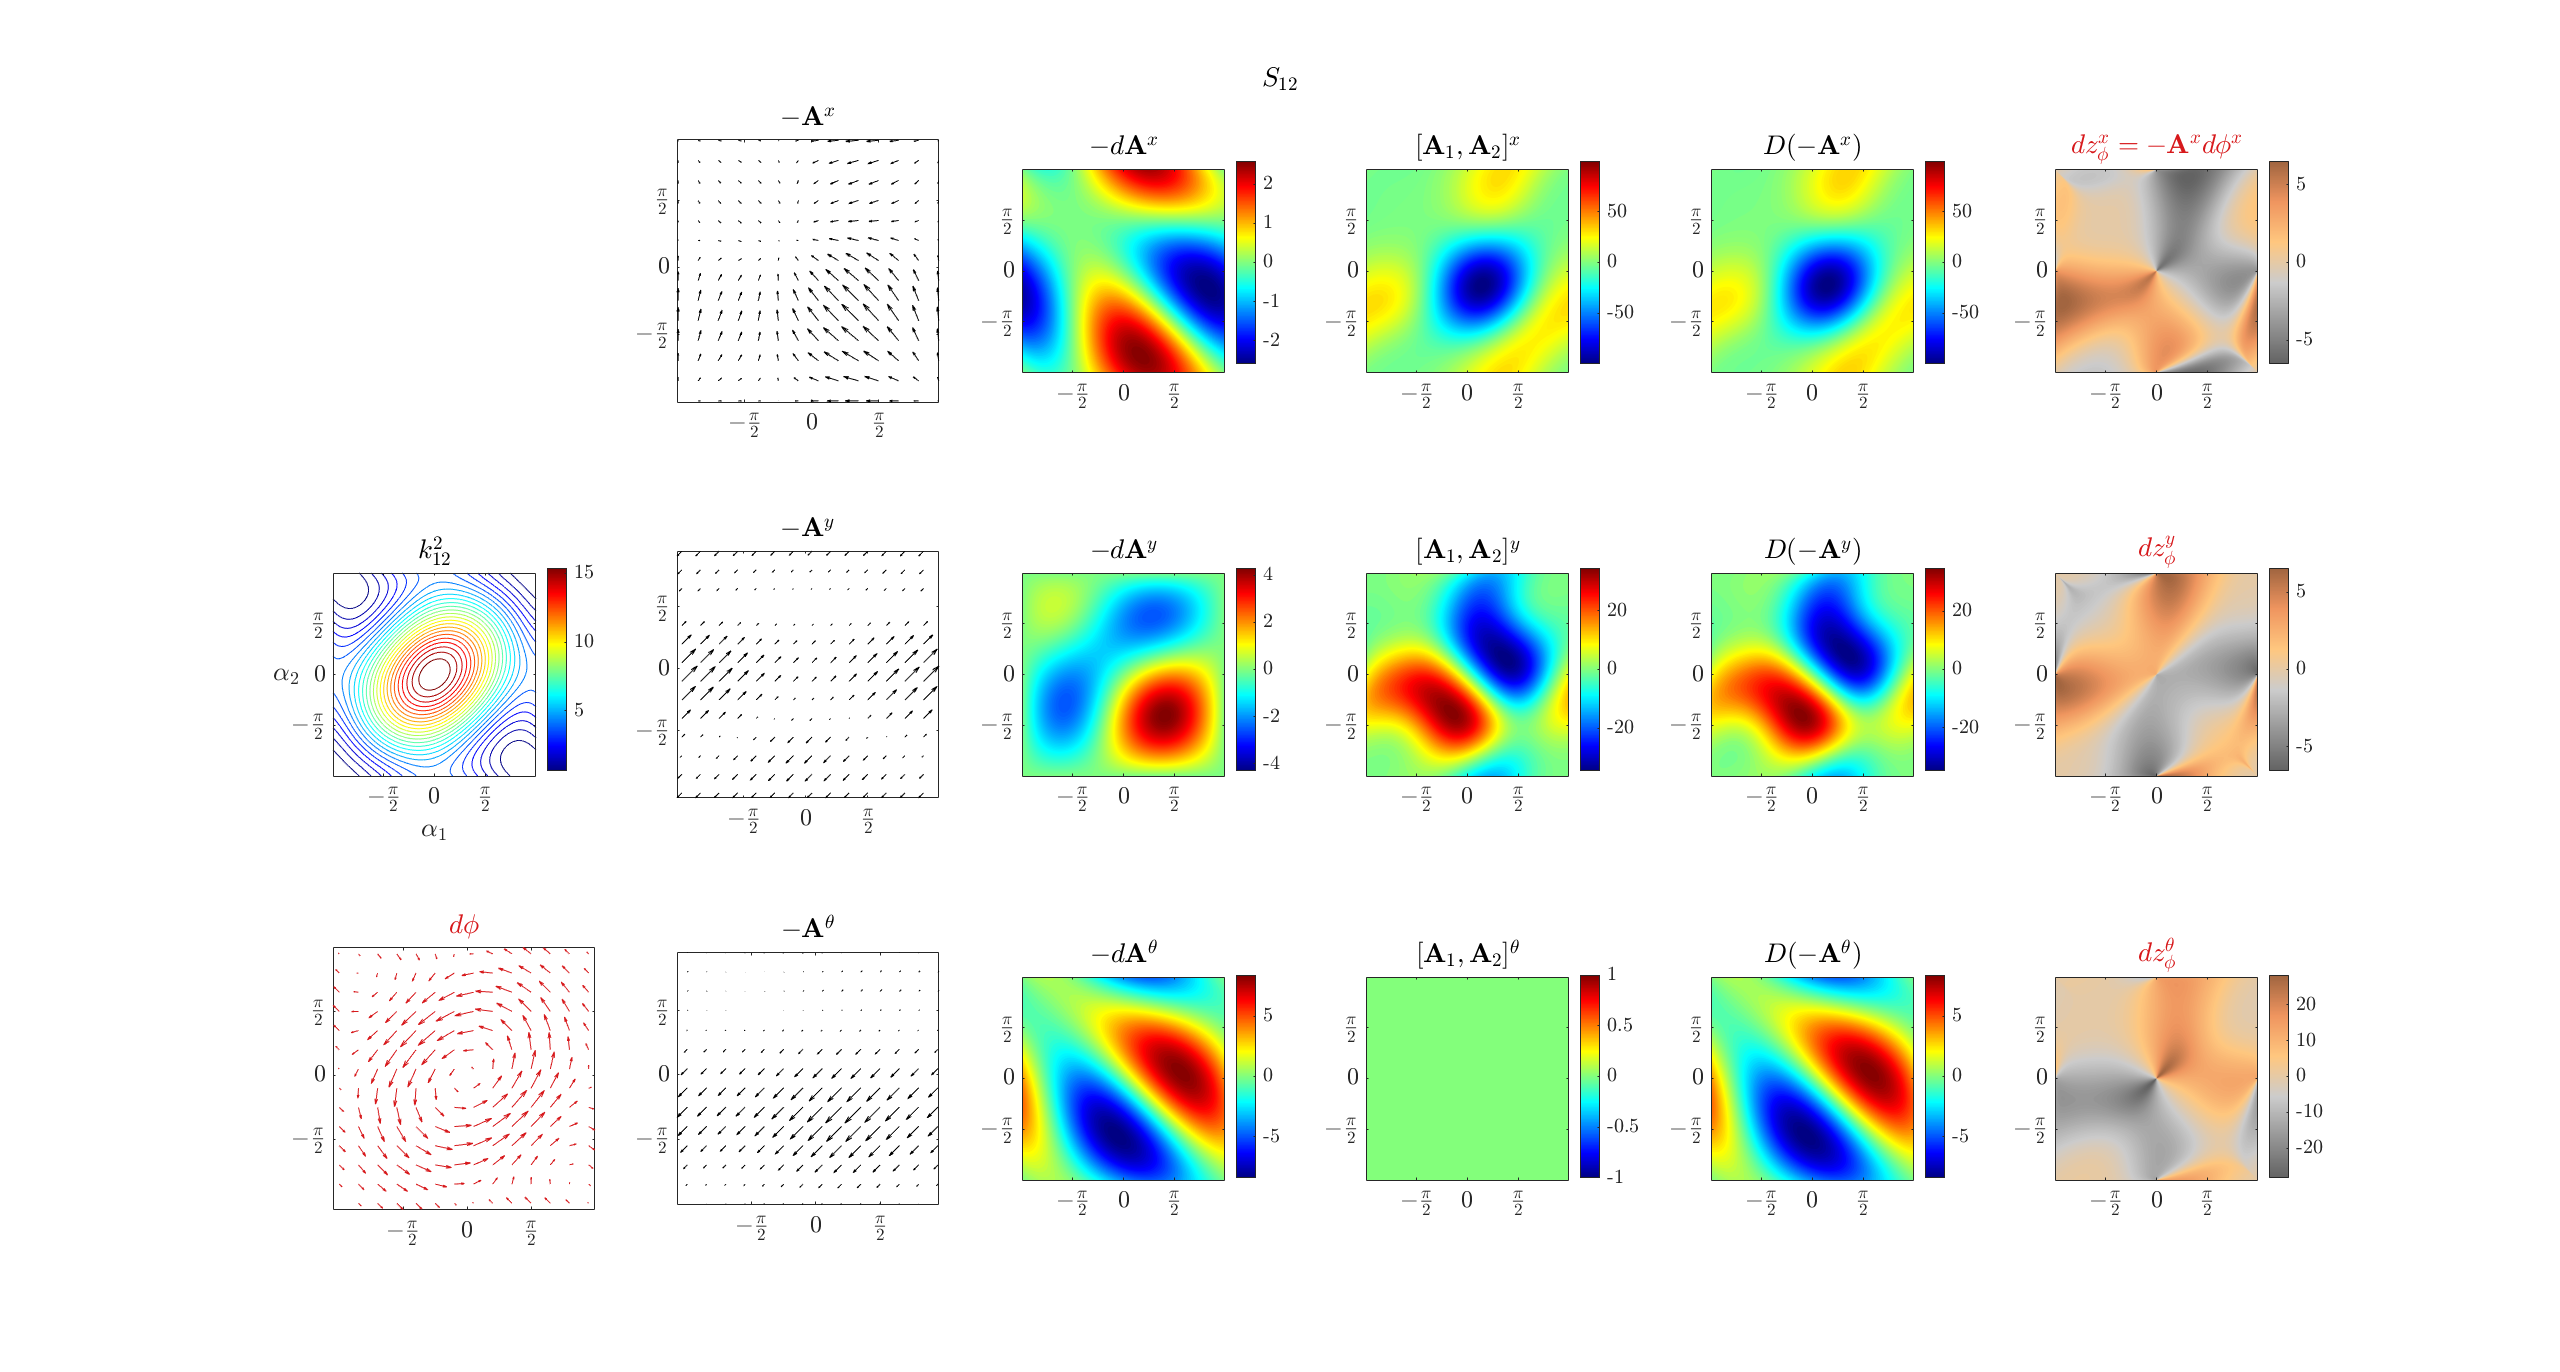

axis equal tight tight; hold on; view(2);
% quiver(ai(iQ,iQ),aj(iQ,iQ),u_sweep(iQ,iQ),v_sweep(iQ,iQ),...
%     'LineWidth',lW_V,'Color','k');
colormap(ax,jet);
if max([abs(min(lb_A_theta_sweep,[],'all')) abs(max(lb_A_theta_sweep,[],'all'))]) ~= -max([abs(min(lb_A_theta_sweep,[],'all')) abs(max(lb_A_theta_sweep,[],'all'))])
    clim([-max([abs(min(lb_A_theta_sweep,[],'all')) abs(max(lb_A_theta_sweep,[],'all'))]), max([abs(min(lb_A_theta_sweep,[],'all')) abs(max(lb_A_theta_sweep,[],'all'))])]);
end
colorbar('TickLabelInterpreter','latex','FontSize',cbarFS);
set(get(gca,'YLabel'),'rotation',0,'VerticalAlignment','middle');
title('$[\mathbf{A}_1,\mathbf{A}_2]^{\theta}$',FontSize=titleFS);
xticks(-pi/2:pi/2:pi/2);
xticklabels({'$-\frac{\pi}{2}$','$0$','$\frac{\pi}{2}$'});
yticks(-pi/2:pi/2:pi/2);
yticklabels({'$-\frac{\pi}{2}$','$0$','$\frac{\pi}{2}$'});
ax = gca;
ax.XAxis.FontSize = tickFS;
ax.YAxis.FontSize = tickFS;

ax = subplot(3,6,12+5); % total lie-bracket/generalized curl
contourf(ai,aj,D_mA_theta_sweep,cfLvl,'LineStyle','none','FaceAlpha',fA);
axis equal tight; hold on; view(2);
% quiver(ai(iQ,iQ),aj(iQ,iQ),u_sweep(iQ,iQ),v_sweep(iQ,iQ),...
%     'LineWidth',lW_V,'Color','k');
colormap(ax,jet);
if max([abs(min(D_mA_theta_sweep,[],'all')) abs(max(D_mA_theta_sweep,[],'all'))]) ~= -max([abs(min(D_mA_theta_sweep,[],'all')) abs(max(D_mA_theta_sweep,[],'all'))])
    clim([-max([abs(min(D_mA_theta_sweep,[],'all')) abs(max(D_mA_theta_sweep,[],'all'))]), max([abs(min(D_mA_theta_sweep,[],'all')) abs(max(D_mA_theta_sweep,[],'all'))])]);
end
colorbar('TickLabelInterpreter','latex','FontSize',cbarFS);
set(get(gca,'YLabel'),'rotation',0,'VerticalAlignment','middle');
title('$D(-\mathbf{A}^{\theta})$',FontSize=titleFS);
xticks(-pi/2:pi/2:pi/2);
xticklabels({'$-\frac{\pi}{2}$','$0$','$\frac{\pi}{2}$'});
yticks(-pi/2:pi/2:pi/2);
yticklabels({'$-\frac{\pi}{2}$','$0$','$\frac{\pi}{2}$'});
ax = gca;
ax.XAxis.FontSize = tickFS;
ax.YAxis.FontSize = tickFS;

ax = subplot(3,6,12+6); % stratified panels
contourf(ai,aj,dz_theta_sweep,cfLvl,'LineStyle','none','FaceAlpha',fA);
axis equal tight; hold on; view(2);
% quiver(ai(iQ,iQ),aj(iQ,iQ),u_sweep(iQ,iQ),v_sweep(iQ,iQ),...
%     'LineWidth',lW_V,'Color',gc_col);
colormap(ax,CUB);
if max([abs(min(dz_theta_sweep,[],'all')) abs(max(dz_theta_sweep,[],'all'))]) ~= -max([abs(min(dz_theta_sweep,[],'all')) abs(max(dz_theta_sweep,[],'all'))])
    clim([-max([abs(min(dz_theta_sweep,[],'all')) abs(max(dz_theta_sweep,[],'all'))]), max([abs(min(dz_theta_sweep,[],'all')) abs(max(dz_theta_sweep,[],'all'))])]);
end
colorbar('TickLabelInterpreter','latex','FontSize',cbarFS);
set(get(gca,'YLabel'),'rotation',0,'VerticalAlignment','middle');
title('$dz_{\phi}^{\theta}$','Color',gc_col,FontSize=titleFS);
xticks(-pi/2:pi/2:pi/2);
xticklabels({'$-\frac{\pi}{2}$','$0$','$\frac{\pi}{2}$'});
yticks(-pi/2:pi/2:pi/2);
yticklabels({'$-\frac{\pi}{2}$','$0$','$\frac{\pi}{2}$'});
% xticklabels({'$-\pi$','$-\frac{\pi}{2}$','$0$','$\frac{\pi}{2}$','$\pi$'});
% yticklabels({'$-\pi$','$-\frac{\pi}{2}$','$0$','$\frac{\pi}{2}$','$\pi$'});
ax = gca;
ax.XAxis.FontSize = tickFS;
ax.YAxis.FontSize = tickFS;

sgtitle('$S_{12}$',FontSize=sgtitleFS);